# Homework 1: Mass-Spring-Damper system

Matteo Scuderi - 1937090

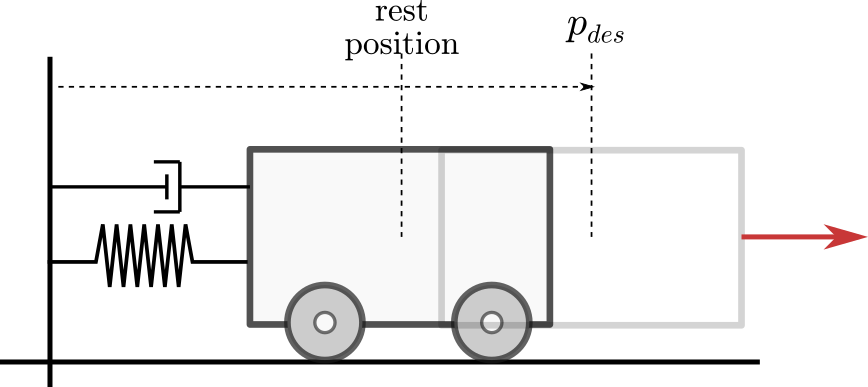

For this first homework, we're going to use the Mass-Spring-Damper system in order to apply all the control techniques studied so far.

The model in use for our plant is:


$$P(s) = \frac{1}{m s^2 + \mu s + k}$$
 
$$f$$


The system parameters $m$, $\mu$ and $k$ will be chosen appropriately. .

clear all

s = tf('s');

% ______ Simulation parameters ______ 

% Simulation Time Vector        
t = 0:0.01:10;

% Frequency ranges
om  = logspace(-2,1,300);
om2 = logspace(-2,5,300); % just a longer frequency range for some plots

We want to reach a desired constant position $p_{des}$. 

% Position Referernce
pdes = 1;  

## Plant analysis

Let's first see how the Plant would behave in open loop (no controller and no feedback). 

We'll use two models with different parameters, respectively chosen to simulate a slightly under-dumped and a slightly over-dumped system. The extremes cases will be left for future further analysis.

% ______ System parameters ______ 
% Underdamped MSD
m1  = 3; % mass
mu1 = 2; % "low" viscous friction coefficient
k1  = 1; % spring coefficient

% Overdamped MSD
m2  = 3; % mass
mu2 = 4; % "high" viscous friction coefficient
k2  = 1; % spring coefficient

% MSD Transfer Functions
MSD1 = 1/(m1*s^2+mu1*s+k1);
MSD2 = 1/(m2*s^2+mu2*s+k2);

zeta1 = mu1/(2*sqrt(k1*m1)); % low damping coefficient
zeta2 = mu2/(2*sqrt(k2*m2)); % high damping coefficient

For the first model, we have $\mu < 2\sqrt{km}$ and the damping coefficient isMSD2


$$\zeta = \frac{\mu}{2 \sqrt{k \, m}} \approx 0.58$$


 therefore we are considering a **lightly** **under damped case. **

Conversely, for the second system we have $\mu > 2\sqrt{km}$ and $\zeta \approx 1.16$, thus we are considering a **lightly** **over damped case.**

#### Bode Magnitude comparison: underdamped vs Overdamped

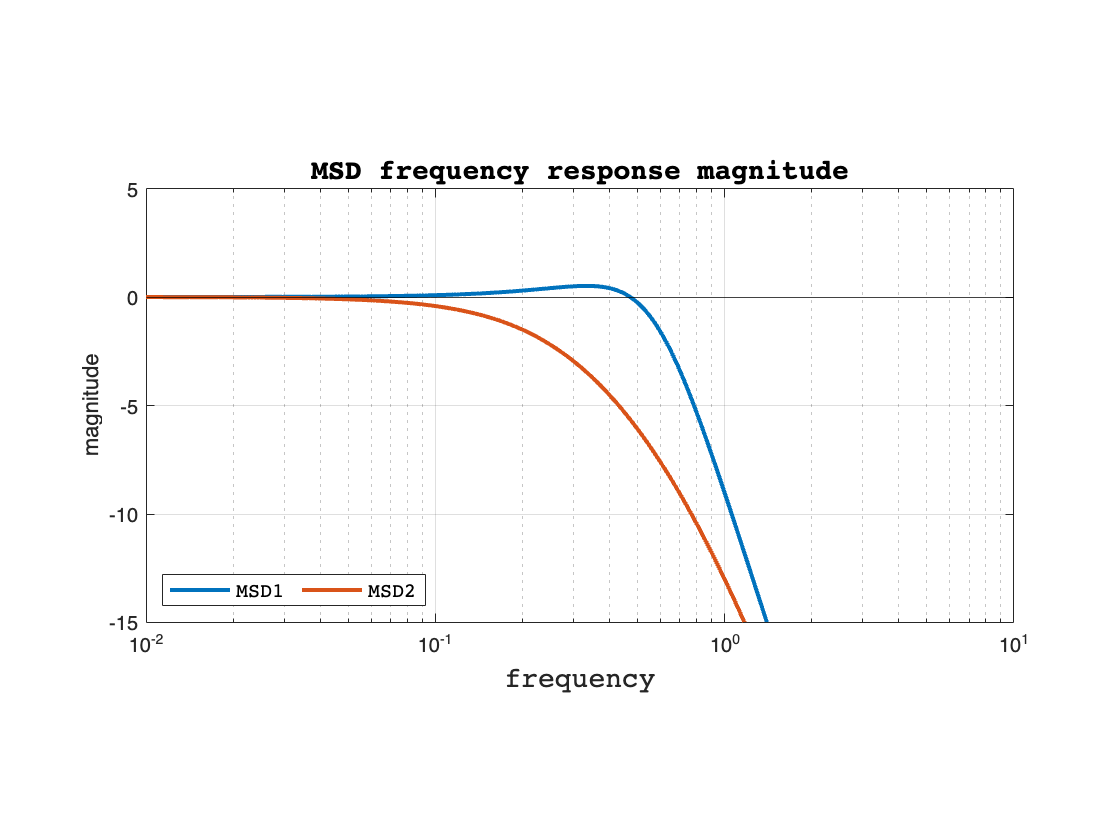

[MSDMag1,~] = bode(MSD1, om);
[MSDMag2,~] = bode(MSD2, om);

% Plot Bode Magnitude comparison: underdamped vs Overdamped
figure()
BodeMSD = semilogx(om, 20*log10(MSDMag1(:)),om, 20*log10(MSDMag2(:)),'LineWidth',2); grid
axis([1E-2,1E1,-15,5])
pbaspect([2,1,1])
yline(0,'k')
ylabel('magnitude')
xlabel('frequency','FontName','courier','FontSize',14)
title('MSD frequency response magnitude','FontName','courier','FontSize',14)
legend('MSD1','MSD2','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)

% Bandwidth comparison
disp("Bandwidth comparison:")

Bandwidth comparison:


[bandwidth(MSD1), bandwidth(MSD2)]

ans =     0.6795    0.3032


% Resonance peak for underdamped system
disp(strcat('Resonance peak: ', num2str(max(MSDMag1)/dcgain(MSD1))))

Resonance peak:1.0607


As expected, we're seeing a resonance peak in the underdamped case, which is however small (being SLIGHTLY underdamped). On the other hand, the second model has a lower bandwidth, which will translate into a even slower response.

Let's verify if our hypotesis are correct.

### Open loop control

To maintain the mass at the desired position $p_{des}$ we need a constant force of $F_{ss} = k\, p_{des}$. If we just apply this constant force, being the MSD asymptotically stable, the response will asymptotically tend to the system gain times the amplitude of the constant input


$$p_{ss} = P(0) \, k \, p_{des} = \frac{1}{k} \, k \, p_{des} = p_{des} $$


with its own dynamics which determines the transient. So this input drives the MSD to the desired location. In simulation we have the following behavior

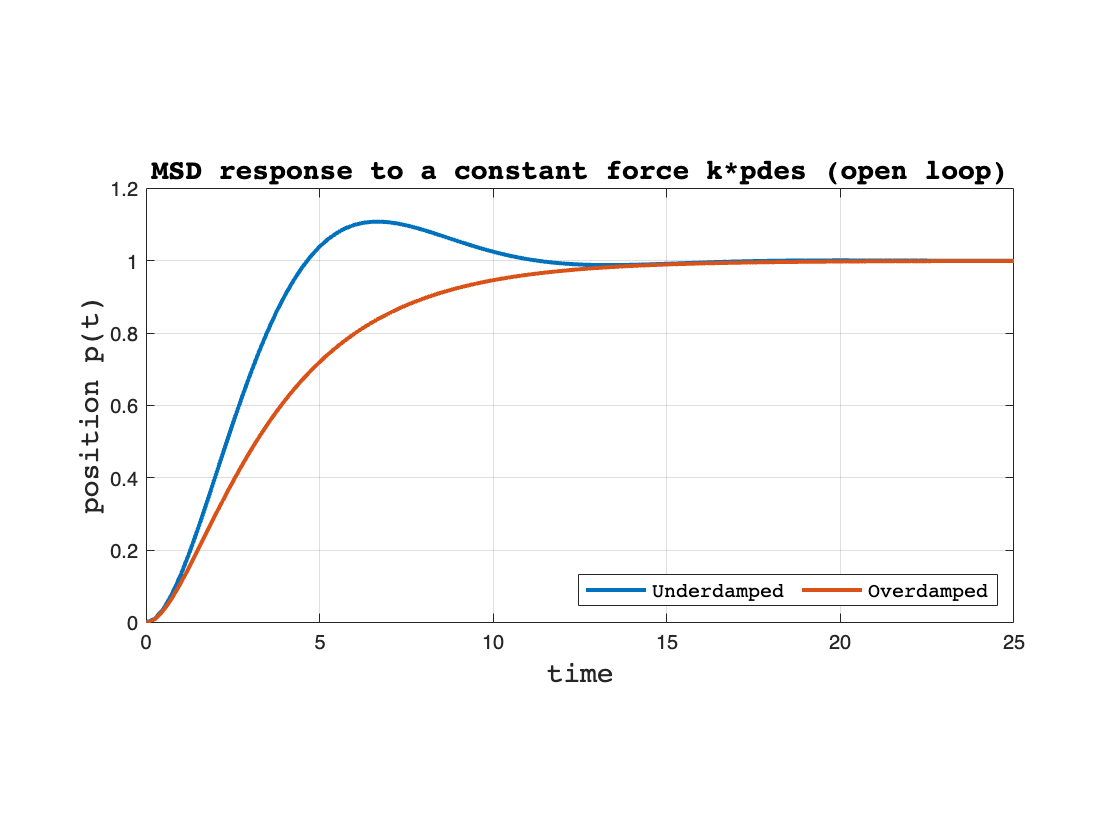

% Step response comparison in open loop

steptime = 25; % set high step time due to low bandwith of the systems
StepOpt = stepDataOptions('StepAmplitude',k1*pdes);

% Step response for the two MSD
[ystep1,time1] = step(MSD1,steptime,StepOpt);
[ystep2,time2] = step(MSD2,steptime,StepOpt);


figure()
plot(time1,ystep1,time2,ystep2,'LineWidth',2); grid
xlabel('time','FontName','courier','FontSize',14)
ylabel('position p(t)','FontName','courier','FontSize',14)
title('MSD response to a constant force k*pdes (open loop)', 'FontName','courier','FontSize',14)
legend('Underdamped','Overdamped' ,'FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2,1,1])

Our hypotesis is confirmed by this graph. The underdumped model presents an overshoot which is justified by the prersence of a resonance peak. On the other hand the overdamped system has a slower response due to lower bandwidth,

**This results are however not enough. We know this open loop control is not robust to parameter variation or uncertainties and to disturbances acting on the system. **

Moreover, we can try to enhance the performance in terms of convergence speed and much more.

## Remark : Control design -  Constant Reference ($P_{des}$)

To obtain a 0 error at steady state with respect to a constant reference, we need to guarantee that the closed loop system is at least of type 1. Since the plant does not have a pole in $s = 0$, we need to add it in the controller - whatever that may be.

We first consider a **classic PID controller** and analyze its performance. We can then try to do something better using our knowledge about $H_\infty$ control. 

# PID Controller Design

We tune our PID for maximizing efficiency in tracking our reference. We also choose a filtered PID for attenuating amplification at high frequency. 

% PID tuning
ops = pidtuneOptions('DesignFocus','reference-tracking');
[C_PID1,info1] = pidtune(MSD1,'PIDF',ops); 
[C_PID2,info2] = pidtune(MSD2,'PIDF',ops);

% Resulting Sensitivities at closed loop
CLoop1 = loopsens(MSD1,C_PID1);  
CLoop2 = loopsens(MSD2,C_PID2);

% ______ Bode Plots quantities: ______ 
% Control Sensitivity
[MagCS_PID1,~]=bode(CLoop1.CSo,om2);  % control sensitivity 1 
[MagCS_PID2,~]=bode(CLoop2.CSo,om2);  % control sensitivity 2 

% Sensitivity
[MagS_PID1,~]=bode(CLoop1.So,om2);  % sensitivity 1 
[MagS_PID2,~]=bode(CLoop2.So,om2);  % sensitivity 2 

% Complementary Sensitivity
[MagT_PID1,PhaseT_PID1]=bode(CLoop1.To,om2);  % complementary sensitivity 1 
[MagT_PID2,~]=bode(CLoop2.To,om2);  % complementary sensitivity 2

Let's first plot the sensitivity and complementary sensitivity functions to verify the correct behaviour

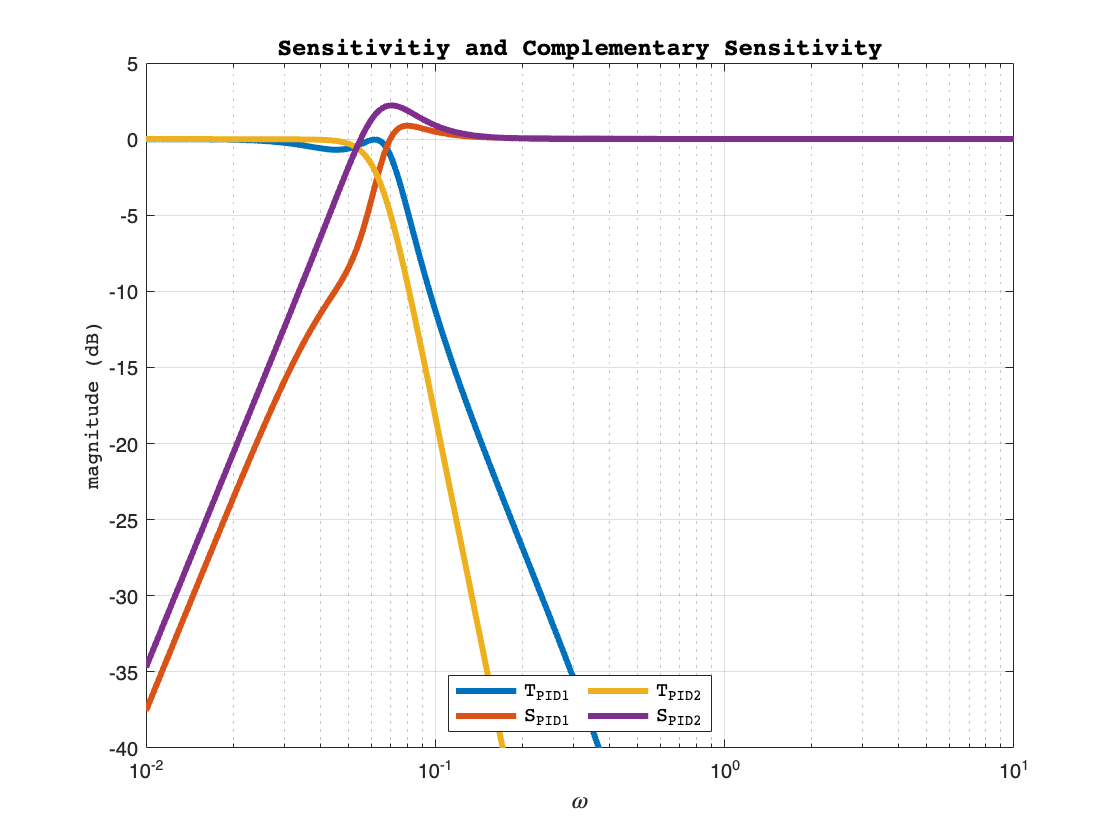

% S(jw) and T(jw) comparison for MSD1 and MSD2
figure()
semilogx(om,20*log10(MagT_PID1(:)),om,20*log10(MagS_PID1(:)), ...
    om,20*log10(MagT_PID2(:)),om,20*log10(MagS_PID2(:)),'LineWidth',3); grid
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Sensitivitiy and Complementary Sensitivity','FontName','courier','FontSize',12)
legend('T_{PID1}','S_{PID1}','T_{PID2}','S_{PID2}','FontName','courier','FontSize',10,...
    'Location','south','NumColumns',3)
ylim([-40,5])
xlim([1e-2,10])

We recognize the usual shapes in both T and S. The sensitivities for the overdamped system have lower bandwidth, which leads to slower response. Both Sensitivity functions present a peak that will translate into an overshoot in the time domain. The underdamped system clearly has the worst performance in that sense, with a large peak that wil lead to oscillations in the transient,

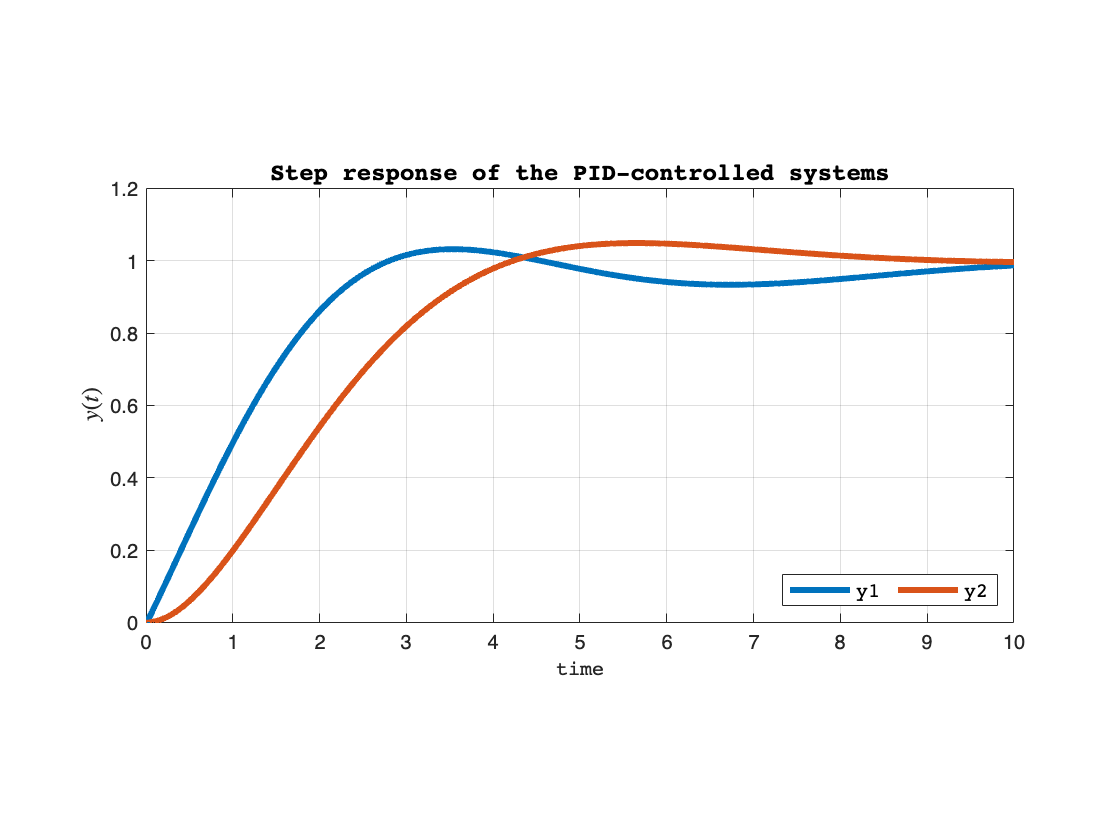

% Step response of the PID controlled system
[y1,t1] = step(CLoop1.To,t); 
[y2,t2] = step(CLoop2.To,t);

figure()
plot(t1,y1(:), t2,y2(:),'LineWidth',3); grid
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Step response of the PID-controlled systems','FontName','courier','FontSize',12)
legend('y1','y2','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
axis([0,10,0,1.2])
pbaspect([2 1 1])

stepinfo(y1,t1)

ans = struct with fields:
         RiseTime: 1.9042
    TransientTime: 8.8278
     SettlingTime: 8.8278
      SettlingMin: 0.8906
      SettlingMax: 1.0322
        Overshoot: 4.5695
       Undershoot: 0
             Peak: 1.0322
         PeakTime: 3.5300


stepinfo(y2,t2)

ans = struct with fields:
         RiseTime: 2.7328
    TransientTime: 7.8578
     SettlingTime: 7.8578
      SettlingMin: 0.8970
      SettlingMax: 1.0491
        Overshoot: 5.2623
       Undershoot: 0
             Peak: 1.0491
         PeakTime: 5.6500


We can observe that as well as a rather slow rise time (almost 2 seconds for the first system, 2.7 for the second one), the transient time is very large. 

We could think of interveining on speeding up our system increasing bandwidth. However, before going down this path, it's worth checking the behaviour of our Control Sensitivity Function.

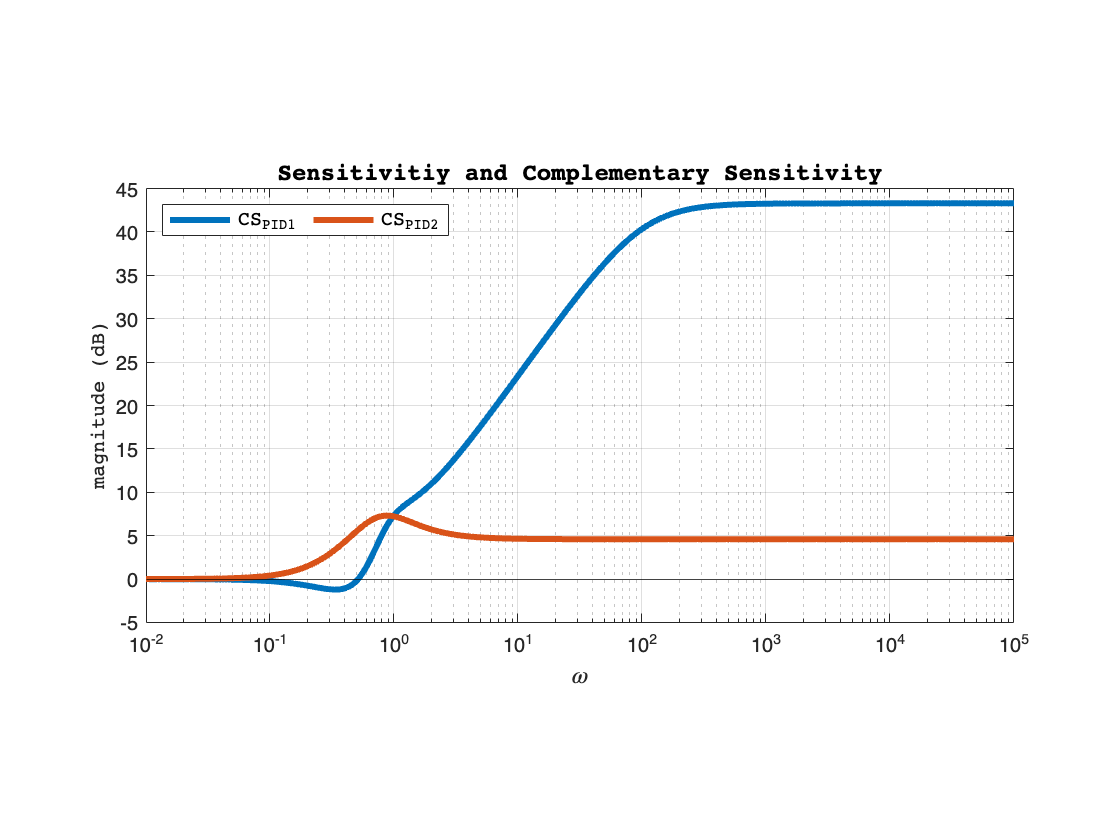

figure
semilogx(om2,20*log10(MagCS_PID1(:)),om2,20*log10(MagCS_PID2(:)), 'LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Sensitivitiy and Complementary Sensitivity','FontName','courier','FontSize',12)
legend('CS_{PID1}','CS_{PID2}','FontName','courier','FontSize',10,...
    'Location','northwest','NumColumns',3)
pbaspect([2 1 1])

The Control Sensitivity Function of the underdamped, PID-controlled system is amplifiying at high frequency, to the point where the control effort required by our controller will be significantly large when using a step reference (or any signal with high frequency content).

On the other hand, thanks to the high damping, the Control Sensitivity Function for the second system behaves very well and we expect a lower control effort, even to  references with high frequency content.

Let's plot the control effort $m(t)$ to verify our intuitions.

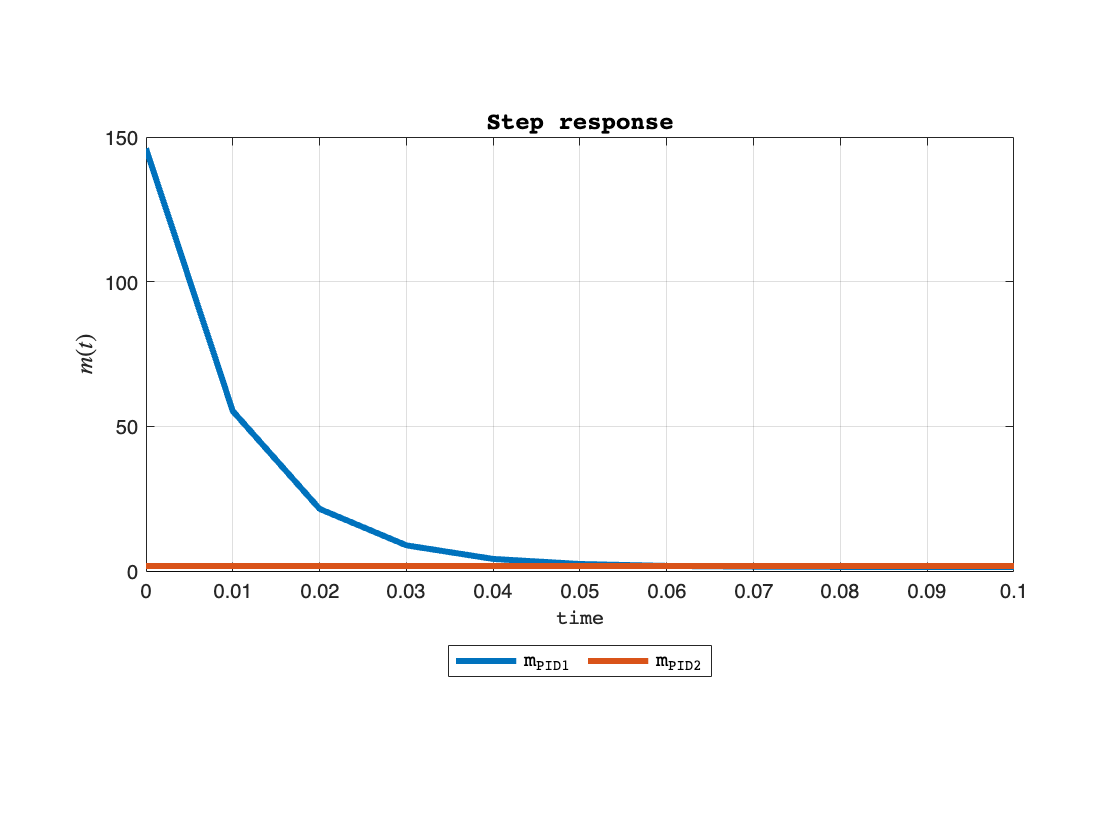

% PID Control effort for the step response
[u1,t1] = step(CLoop1.CSo,t); % output of the control sensitivity function to a unit step
[u2,t2] = step(CLoop2.CSo,t); % output of the control sensitivity function to a unit step

figure
plot(t1,u1(:), t2,u2(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Step response','FontName','courier','FontSize',12)
legend('m_{PID1}','m_{PID2}','FontName','courier','FontSize',10,...
    'Location','southoutside','NumColumns',3)
xlim([0,0.1])
pbaspect([2 1 1])

% Maximum Control effort ratio
max(u1)/max(u2)

ans = 77.6999

Like we expected, the control effort required by the first system is significantly larger when given a step reference, as a matter of fact the maximum control effort required is 77 times larger. Even if we're satisfied with the second control effort, we have to remember that the transient time is still significantly large, and so we can't be satisfied with this performance.

It makes  sense to use $H_\infty$ control for satisfiying stricter specifications.

# $H_\infty$** Control Design**

Let's procede one step at the time. First of all, let's keep in mind our goal.

We're going to introduce (one at the time and then we'll combine them) three weight functions: $w_S(s) , w_T(s) , w_{S_{u}}(s) $, each accurately designed to bound the respective Sensitivity function, in order to meet certain specifications.

We're then going to solve a minimization problem in order to find a Stabilizing Controller such that:


$$1)\  \|{S(s)  w_S(s)\} \|_{\infty} < 1 \\
2)\  \|{S_u(s)  w_{U_s}(s)\} \|_{\infty} < 1 \\
3)\  \|{T(s)  w_T(s)\} \|_{\infty} < 1 \\
$$


We're going to **base our controller only on the slightly under-damped model, **since it appears to be more challenging**.** 

Once that's done, we'll check our performance with respect to different references.

### Sensitivity Weight

As a first step, we're going to design a sensitivity weight as:


$$w_S(s)\ =\ \left(\frac{s/(M _S)^{\frac{1}{n}} + B_{3S}}{(s + B_{3S} (A_S)^{\frac{1}{n}}}\right)^n$$
 

Choosing:

- $A_S$ "small" for tracking references at low frequency 

- $B_{3S}$ "large" to speed up the system response, but "not too large" for control effort's sake

- $M_S
$ "small" to minimize resonance peak 

- $n$ arbitrary, for controlling the weight sensitivity functions's "slope". We'll go with 1 for semplicity

We could try to use similar parameters to the ones obtained with a classic controller (for example, a PID) but instead, let's try to push our boundaries to maximize the desired performances.

% Sensitivity Weight
Ms1 = 1.01;
B3s1 = 5;
As1 = 0.01;
n1 = 1;

wS1 = ((s/(Ms1)^(1/n1)+B3s1)/(s+B3s1*(As1)^(1/n1)))^n1;

#### Preliminary observation: Bandwidth

One of the reasons we're not satisfied with a simple PID controller is the slow rate of converge to the reference. Therefore, we're pushing our bandwidth significantly higher than the plant's one.

We know we're going to pay the price in terms of high control effort, but we'll try to compromise in order to get much faster transients. Moreover, increasing the Sensitivity bandwidth entails increasing the Complementary sensitivity bandwidth. On one hand, we're making the system more sensitive to measurement noise, but on the other hand we're going to be able to track sinusoidal references at "low to medium" frequency with no attenuation in module. As for the phase, we'll need to be a little more catious about it, but we'll discuss that when it's time.

### Compute the controller (start with $w_s$ only)

Using mixsyn, we'll find the minimum stabilizing controller such that  $ \|{S(s)  w_s(s)\} \|_{\infty} < 1$ holds true.

% Controller Synthesis
[C1,CL1,GAM1] = mixsyn(MSD1,wS1,[],[]);
GAM1

GAM1 = 0.9953

With this choice of values we have $ \|{S(s)  w_s(s)\} \|_{\infty} < 0.9967$, very close to the upper bound 1. Therfore, we can say we're satisfied with the controller found and we can proceed with the analysis.

Let's get the sensitivities functions and do some plotting.

% Closed Loop Sensitivities
SF1 = loopsens(MSD1,C1);

% ______ Bode quantities ______ 
[magwS1,~]=bode(wS1,om2);             % sensitivity weight
[magS1,~]=bode(SF1.So,om2);           % sensitivity
[magCS1,~]=bode(SF1.CSo,om2);         % control sensitivity
[magT1,phaseT1]=bode(SF1.To,om2);     % complementary sensitivity
[magL1,~]=bode(SF1.Li,om2);           % loop function
[magC1,~]=bode(C1,om2);               % optimal controller
[magwSS1,~]=bode(wS1*SF1.So,om2);     % weighted sensitivity

#### Sensitivity Function's behaviour

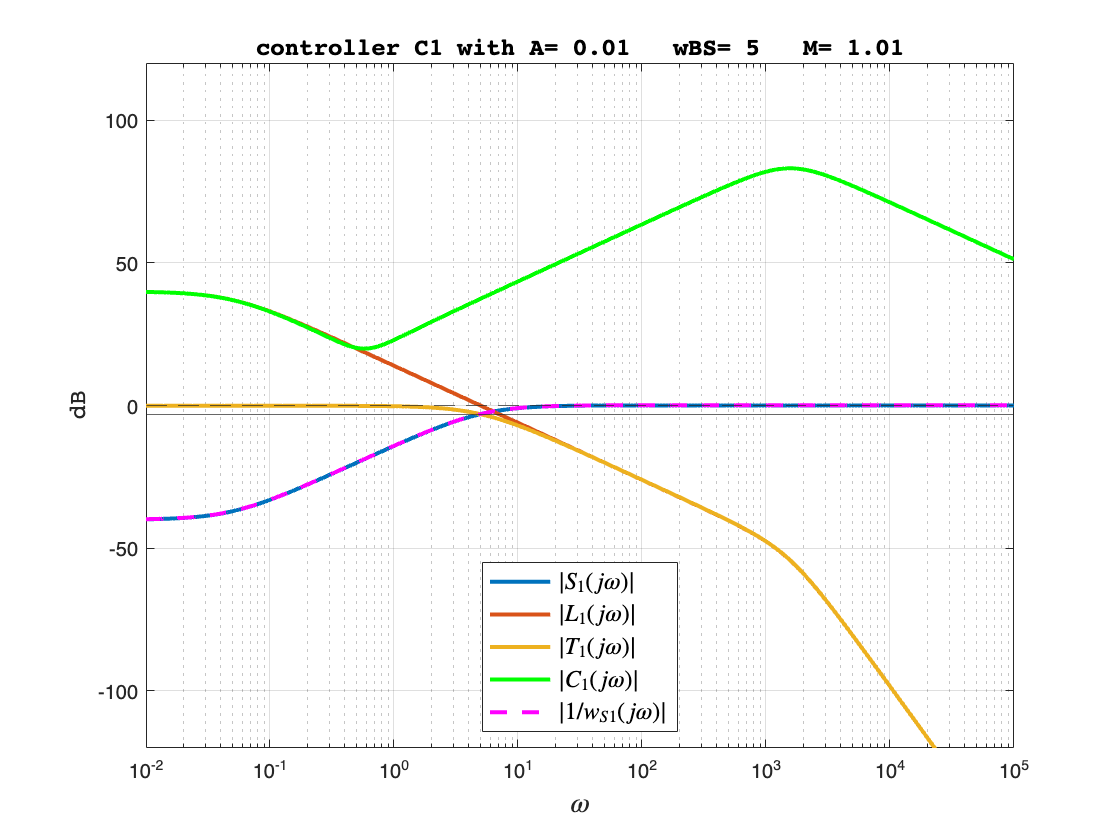

figure
Plot3 = semilogx(om2,20*log10(magS1(1,:)),...
    om2,20*log10(magL1(1,:)),om2,20*log10(magT1(1,:)),...
    om2,20*log10(magC1(1,:)),om2,-20*log10(magwS1(1,:)),'--'); grid
set(Plot3,'LineWidth',2)
set(Plot3(4),'Color','Green')
set(Plot3(5),'Color','magenta')
yline(0,'--')
yline(-3)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
legC = legend('$|S_1(j\omega)|$','$|L_1(j\omega)|$','$|T_1(j\omega)|$','$|C_1(j\omega)|$','$|1/w_{S1}(j\omega)|$',...
    'Interpreter','latex','Location','south');
set(legC,'FontSize',12)
title(['controller C1 with A= ' num2str(As1) '   wBS= ' num2str(B3s1) ...
          '   M= ' num2str(Ms1)],'FontName','courier','FontSize',12);
ylim([-120,120])
xlim([1.e-2,1.e+5])

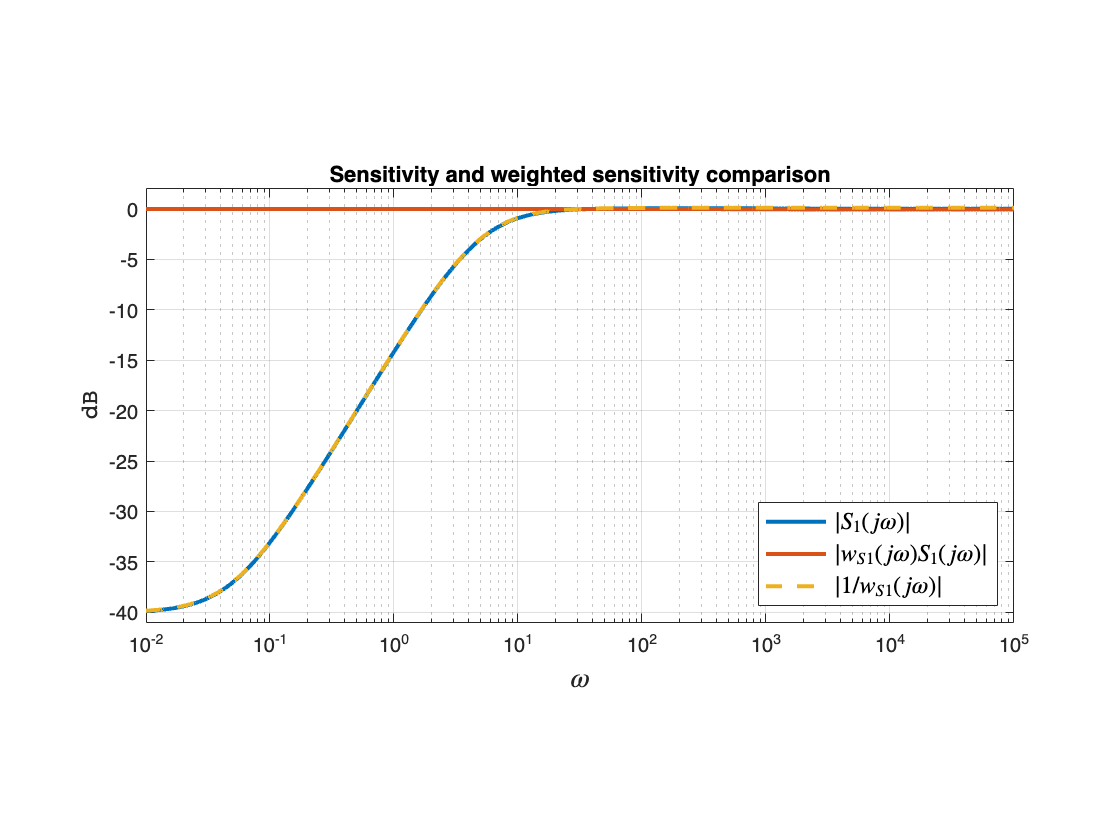

figure
Plot4 = semilogx(om2,20*log10(magS1(1,:)),om2,20*log10(magwSS1(1,:)),...
                 om2,-20*log10(magwS1(1,:)),'--'); grid
set(Plot4,'LineWidth',2)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
leg4 = legend('$|S_1(j\omega)|$','$|w_{S1}(j\omega)S_1(j\omega)|$','$|1/w_{S1}(j\omega)|$','Location','SouthEast',...
        'Interpreter', 'latex');
title('Sensitivity and weighted sensitivity comparison')
set(leg4,'FontSize',12)
ylim([-41,2])
xlim([1.e-2,1.e+5])
pbaspect([2,1,1])

### Control Sensitivity Comparison

As we know, increasing bandwidth comes at a price. We expect a larger control effort with this new controller. Let's first compare the control sensitivity functions to anticipate the behaviour.

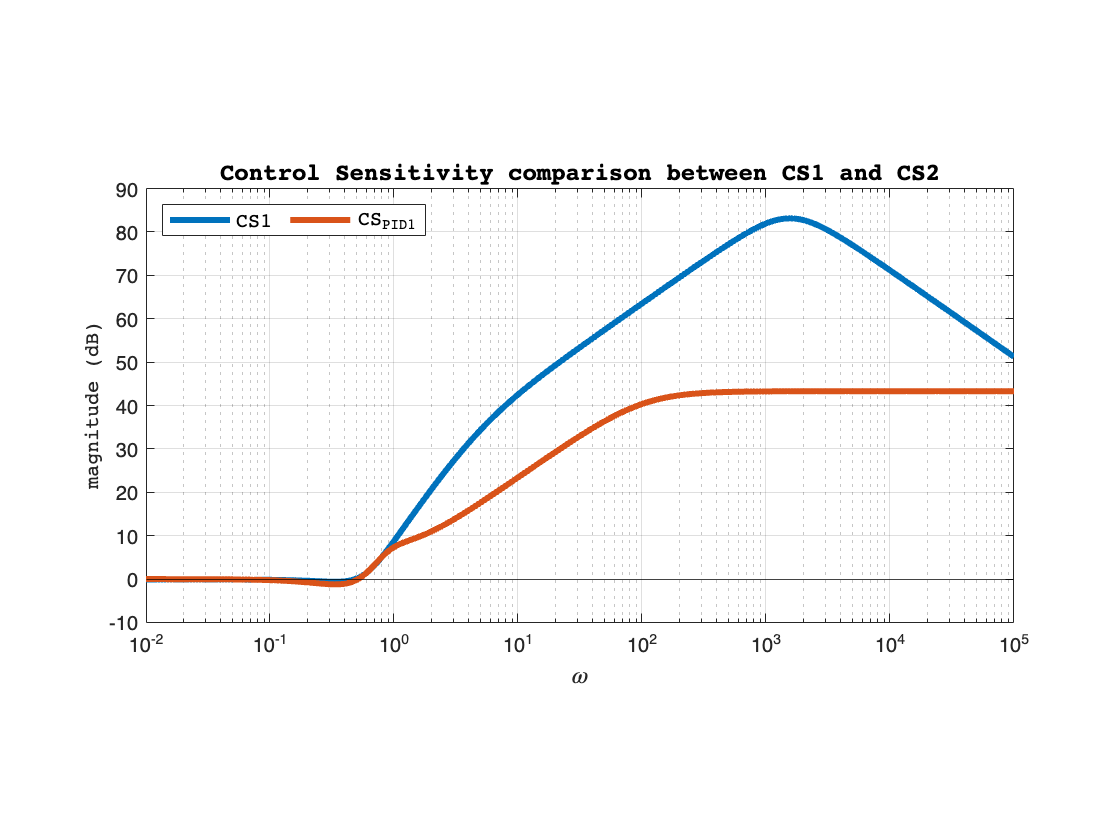

figure
semilogx(om2,20*log10(magCS1(:)), ...
    om2,20*log10(MagCS_PID1(:)),'LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Control Sensitivity comparison between CS1 and CS2','FontName','courier','FontSize',12)
legend('CS1','CS_{PID1}', 'FontName','courier','FontSize',10,...
    'Location','northwest','NumColumns',3)
pbaspect([2 1 1])

Unfortunately, the new control sensitivity function starts amplifying at a even lower frequency. The control effort will be therefore huge with high frequency references. Let's compare the step response in terms of control effort (output of the control sensitivity function) and tracking (output of the Complementary sensitivity function).

#### Control Effort comparison

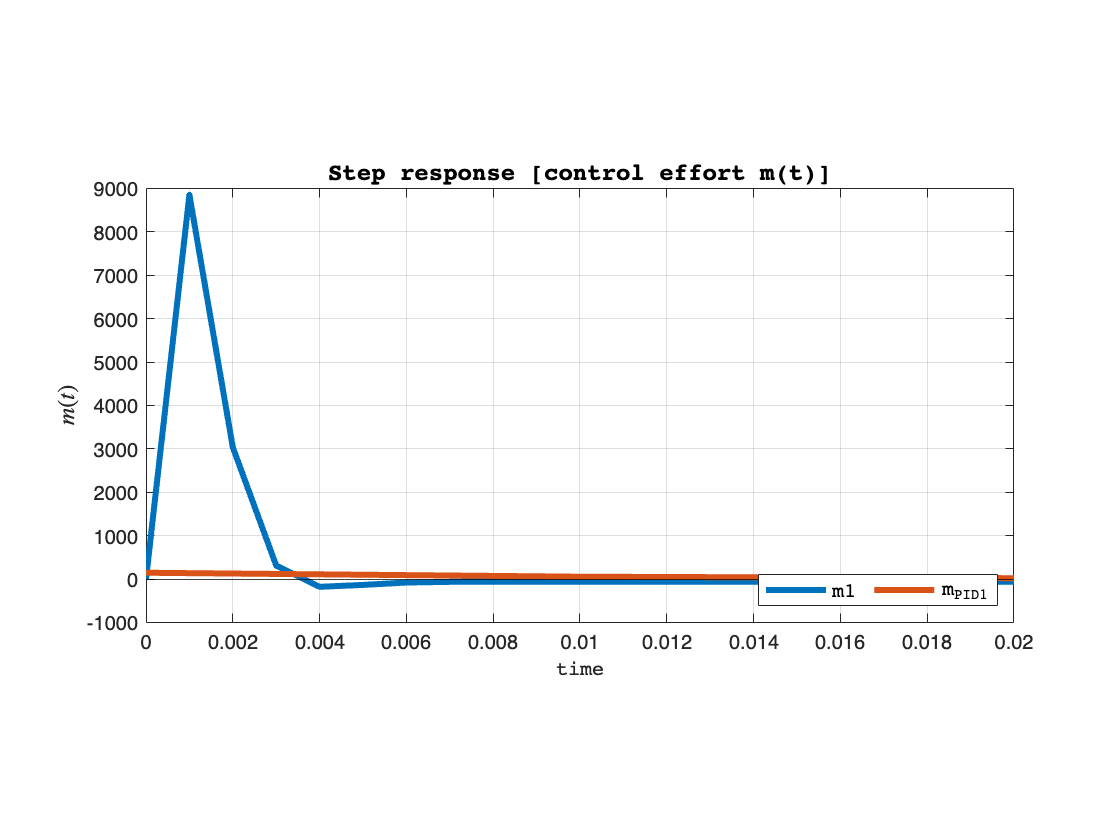

tH1 = 0:0.001:10;
[uH_1,tH1] = step(SF1.CSo, tH1); % output of the control sensitivity function to a unit step

figure
plot(tH1,uH_1(:),t1,u1(:), 'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Step response [control effort m(t)]','FontName','courier','FontSize',12)
legend('m1','m_{PID1}','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
xlim([0, 0.02])
pbaspect([2 1 1])

The control effort is not even comparable, it's clear that the $H_\infty
$ controller is simply not feasible in real life at its current state.

However, it's worth noticing that **the controller** (like any other $H_\infty
$ controller we'll use) **is "canceling" the plant **in orther to satisfy the specifications imposed. We can check it simply seeing the simplification occurring in L(s).

[zero(C1) pole(MSD1)]

ans =   -0.3333 + 0.4714i  -0.3333 + 0.4714i
  -0.3333 - 0.4714i  -0.3333 - 0.4714i


#### Output comparison

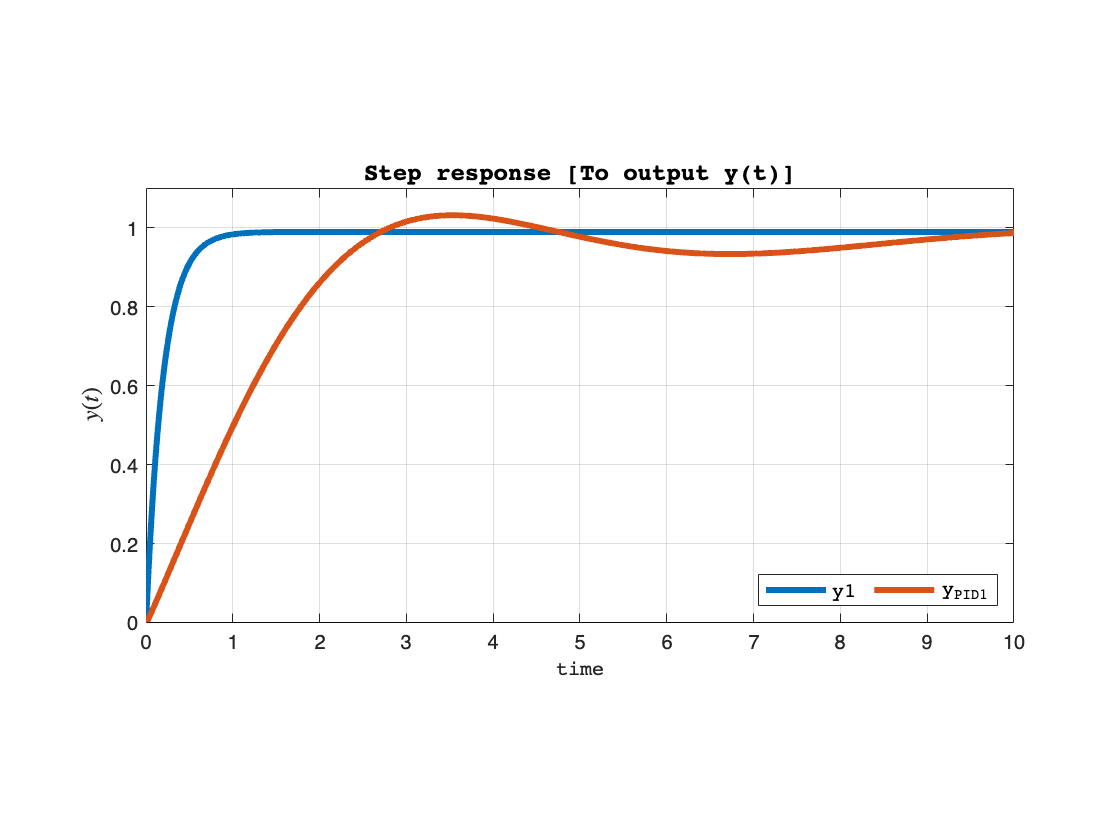

[yH_1,tH1] = step(SF1.To,t);

figure
plot(tH1,yH_1(:), t1,y1(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Step response [To output y(t)]','FontName','courier','FontSize',12)
legend('y1','y_{PID1}','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
axis([0,10, 0,1.1])
pbaspect([2 1 1])

stepinfo(yH_1, tH1)

ans = struct with fields:
         RiseTime: 0.4351
    TransientTime: 0.7758
     SettlingTime: 0.7758
      SettlingMin: 0.8925
      SettlingMax: 0.9900
        Overshoot: 4.7473e-11
       Undershoot: 0
             Peak: 0.9900
         PeakTime: 9.2800


stepinfo(y1, t1)

ans = struct with fields:
         RiseTime: 1.9042
    TransientTime: 8.8278
     SettlingTime: 8.8278
      SettlingMin: 0.8906
      SettlingMax: 1.0322
        Overshoot: 4.5695
       Undershoot: 0
             Peak: 1.0322
         PeakTime: 3.5300


Results are much much better in terms of tracking velocity and we observe no overshoot at all. The tracking error is also very small. However, the H-infinity effort is clearly unrealizable in real life.

More generally, the problem arises when tracking any reference with medium-to-high frequency content. The shape of the $S_u$ suggests a very large control effort for any signal of that kind. We need to impose an upper bound for the control sensitivity function in order to obtain an acceptable performance.

## Weighted Control Sensitivity function

Let's define a weight for the control sensitivity function that's going to bound our control effort, especially when dealing with references with high frequency content.

Let's consider two cases: in the first one, we'll use a constant weight that will bound just the module of the Cs function; in the second case, we'll use a properly deisgned function to impose bandwith and module at low and high frequency.


$$w_{S_u}(s)\ =\ \frac{s+{\frac{B_{3S_u}}{M _{S_u}}}}{A_{S_u}\  s+ B_{3S_u} }}}$$


% Control sensitivity weight parameters
Msu1 = 200;
B3su1 = 10^4;
Asu1 = 0.01;

% Control sensitivity weight
wSu1 = ((s+(B3su1/Msu1))/(Asu1*s+B3su1));

% Constant weight function
KSu1 = 1/100;

% H-inf synthesis with constant weight
[C2,CL2,GAM2] = mixsyn(MSD1,wS1,KSu1,[]);

% H-inf synthesis with non-constant weight
[C3,CL3,GAM3] = mixsyn(MSD1,wS1,wSu1,[]);

[GAM2;GAM3]

ans =     1.5548
    1.4267


#### Remark

The $H_\infty
$ norm of both weighted sensitivity function $w_{S_u}S_u$ is larger than 1. This means that the specifications we're asking are too strict and won't be met by our closed loop system.

Before trying to change all the weights, let's instead analyse **where** these specifications are not met, and wether or not we can accept such underperformances.

% Closed loop with constant weight
SF2 = loopsens(MSD1,C2);

% ______ Bode quantities ______ 
[magS2,~]=bode(SF2.So,om2);         % sensitivity
[magCS2,~]=bode(SF2.CSo,om2);         % control sensitivity
[magT2,phaseT2]=bode(SF2.To,om2);         % complementary sensitivity
[magL2,~]=bode(SF2.Li,om2);         % loop function
[magC2,~]=bode(C2,om2);             % optimal controller

% Closed loop with non-constant weight
SF3 = loopsens(MSD1,C3);

% ______ Bode quantities ______
[magwSu1,~]=bode(wSu1,om2);          % weight
[magS3,~]=bode(SF3.So,om2);         % sensitivity
[magCS3,~]=bode(SF3.CSo,om2);         % control sensitivity
[magT3,phaseT3]=bode(SF3.To,om2);         % complementary sensitivity
[magL3,~]=bode(SF3.Li,om2);         % loop function
[magC3,~]=bode(C3,om2);             % optimal controller


### Sensitivity and Complementary sensistivity comparison

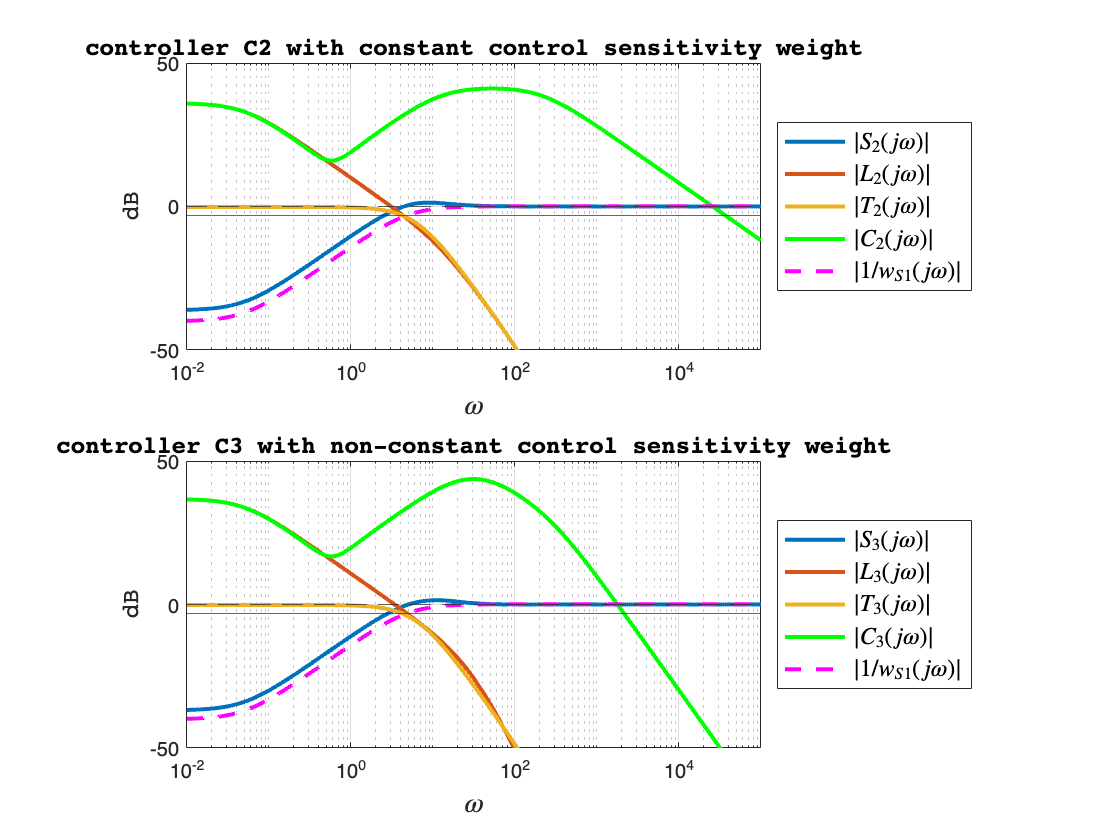

figure
subplot(2,1,1)
Plot5 = semilogx(om2,20*log10(magS2(1,:)),...
    om2,20*log10(magL2(1,:)),om2,20*log10(magT2(1,:)),...
    om2,20*log10(magC2(1,:)),om2,-20*log10(magwS1(1,:)),'--'); grid
set(Plot5,'LineWidth',2)
set(Plot5(4),'Color','Green')
set(Plot5(5),'Color','magenta')
yline(0,'--')
yline(-3)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
legC = legend('$|S_2(j\omega)|$','$|L_2(j\omega)|$','$|T_2(j\omega)|$','$|C_2(j\omega)|$','$|1/w_{S1}(j\omega)|$',...
    'Interpreter','latex','Location','eastoutside');
set(legC,'FontSize',12)
title(['controller C2 with constant control sensitivity weight'],'FontName','courier','FontSize',12);
ylim([-50,50])
xlim([1.e-2,1.e+5])
pbaspect([2 1 1])

subplot(2,1,2)
Plot6 = semilogx(om2,20*log10(magS3(1,:)),...
    om2,20*log10(magL3(1,:)),om2,20*log10(magT2(1,:)),...
    om2,20*log10(magC3(1,:)),om2,-20*log10(magwS1(1,:)),'--'); grid
set(Plot6,'LineWidth',2)
set(Plot6(4),'Color','Green')
set(Plot6(5),'Color','magenta')
yline(0,'--')
yline(-3)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
legC = legend('$|S_3(j\omega)|$','$|L_3(j\omega)|$','$|T_3(j\omega)|$','$|C_3(j\omega)|$','$|1/w_{S1}(j\omega)|$',...
   'Interpreter','latex','Location','eastoutside');
set(legC,'FontSize',12)
title(['controller C3 with non-constant control sensitivity weight'],'FontName','courier','FontSize',12);
ylim([-50,50])
xlim([1.e-2,1.e+5])
pbaspect([2 1 1])

#### Real sensitivities vs weights

The biggest "underperformance" we can see is definetely the behaviour of the sensitivity function at low frequency. It's clearly above our perforfmance index $A_S$. This will lead to a larger tracking error with respect to a constant reference.

Since the behaviour at low frequency is still acceptable, we can consciously "trade" a slightly larger tracking error with a significantly smaller control effort and continue with our analysis.

Let's now quantify this improvement in terms of control effort.

### Control Sensitivity comparison

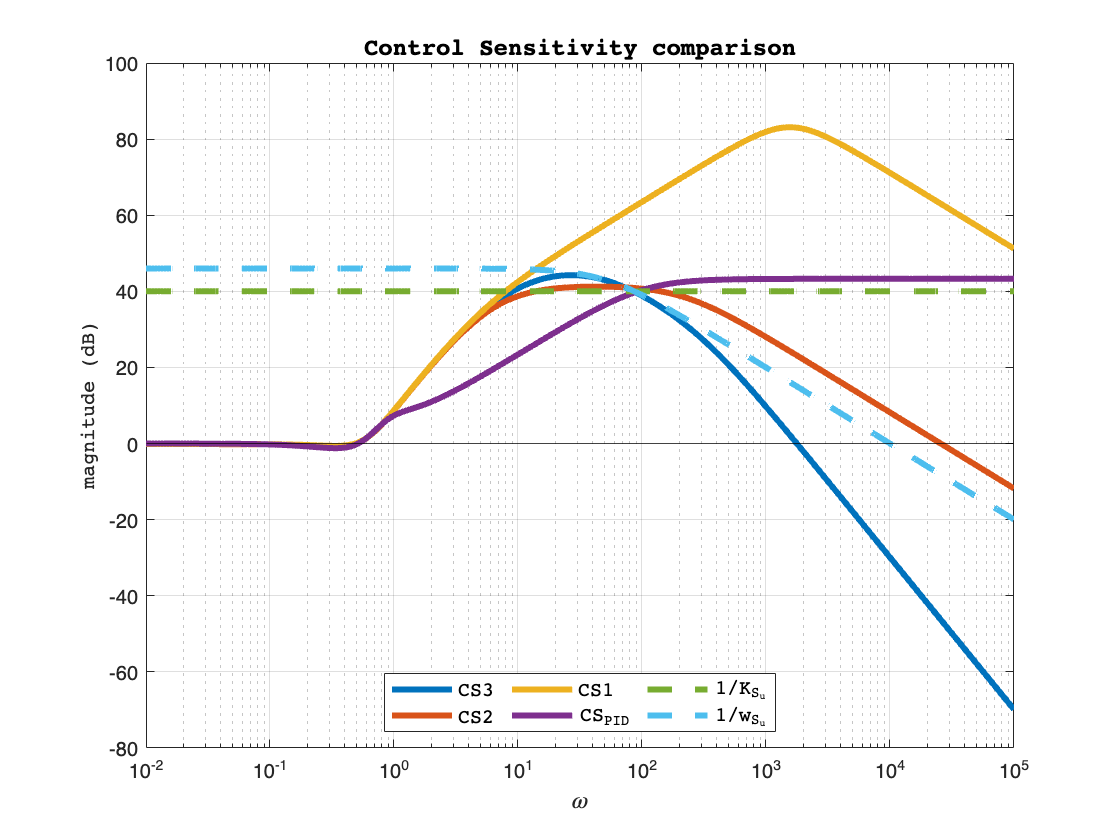

figure
semilogx(om2,20*log10(magCS3(:)),om2,20*log10(magCS2(:)),om2,20*log10(magCS1(:)), ...
    om2, 20*log10(MagCS_PID1(:)),om2,-20*log10(KSu1)*ones(length(MagCS_PID1),1),'--', ...
    om2,-20*log10(magwSu1(:)),'--','LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Control Sensitivity comparison','FontName','courier','FontSize',12)
legend('CS3','CS2','CS1','CS_{PID}','1/K_{S_u}','1/w_{S_u}','FontName','courier','FontSize',10,...
    'Location','south','NumColumns',3)

### Control Effort

Let's compare the control effort with the other ones. Keep in mind that the previous $H_\infty
$ controller (C1) had an effort peak above 14.000, therefore won't be plotted.

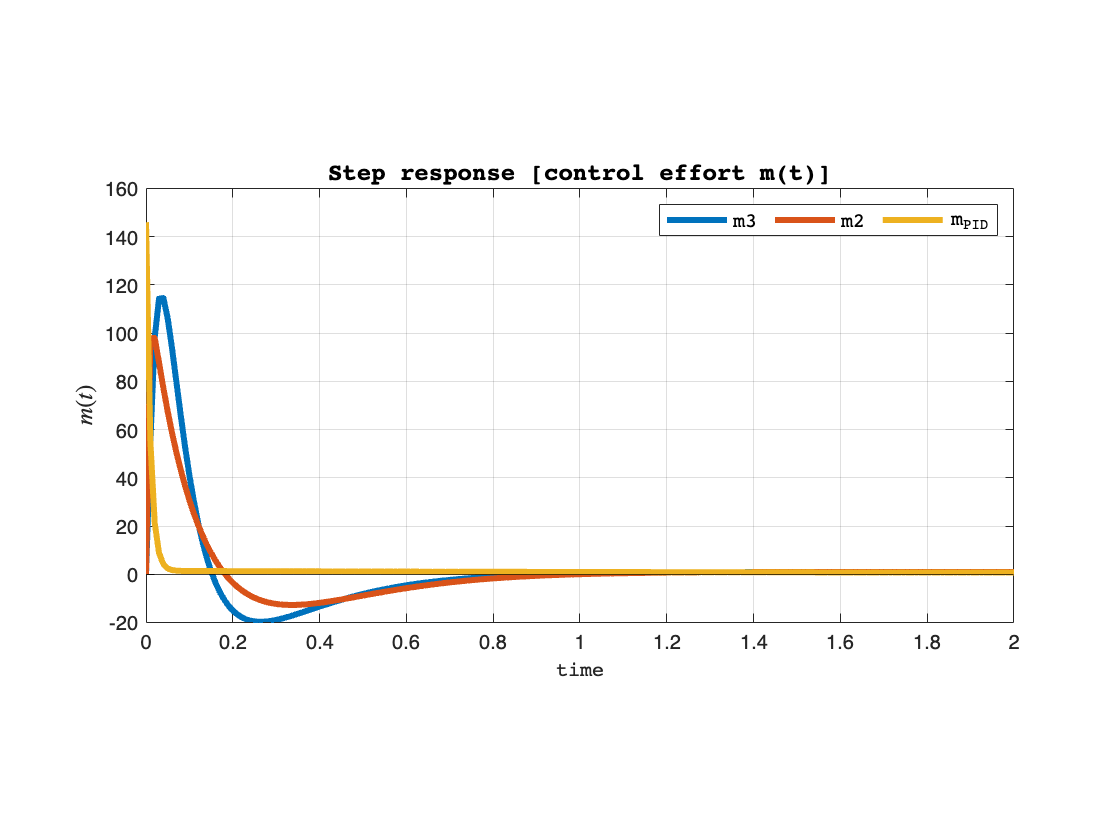

% Control effort
[uH_2,tH2] = step(SF2.CSo,t);
[uH_3,tH3] = step(SF3.CSo,t);


figure
plot(tH3, uH_3(:),tH2, uH_2(:),t1,u1(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Step response [control effort m(t)]','FontName','courier','FontSize',12)
legend('m3','m2','m_{PID}','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)
xlim([0,2])
pbaspect([2 1 1])

We have decreased the maximum control effort with respect to a step reference. The $C_{S_u}$ with cononstant weight has a lower peak, but also a higher bandwidth. The other $C_{S_u}$, with it's lower bandwidth, is more robust to high frequency disturbances and therefore we'll use it for further comparisons.

#### Output comparison

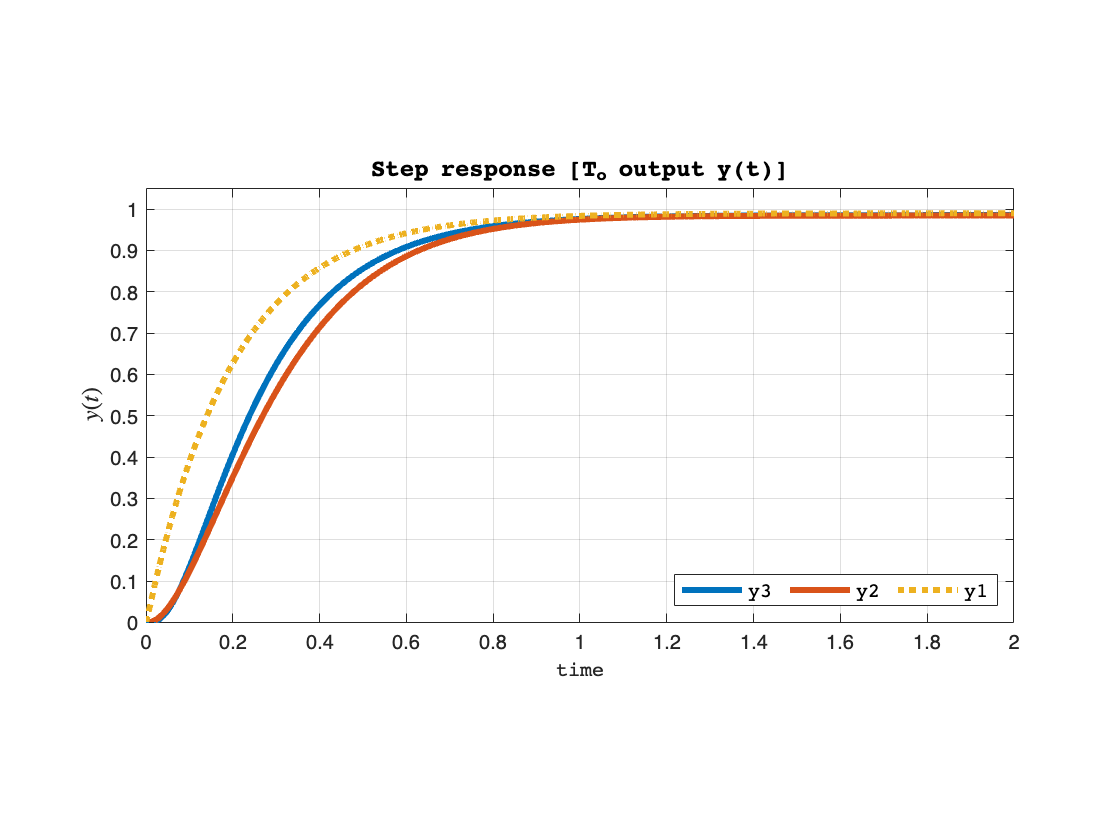

% Step response
[yH_2,~] = step(SF2.To,t);
[yH_3,~] = step(SF3.To,t);

figure
plot(tH3,yH_3(:),tH2,yH_2(:),tH1,yH_1(:),':','LineWidth',3); grid
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Step response [T_o output y(t)]','FontName','courier','FontSize',12)
legend('y3','y2','y1','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
axis([0,2, 0,1.05])
pbaspect([2 1 1])

Excluding the PID response which is far slower, as analysed before, we kept the y1 (dotted line) as reference for "ideal behaviour" (with virtually unlimited control effort available). We observe a very slight decrease in the convergence speed and tracking error. On the other hand, control effort has been drastically reduced.

In terms of convergence speed, we see a slightly better performance with the C3 controller, the one with non constant control sensitivity weight and lower ${\textrm{B3}}_{S_u }$ and, conversely, slightly higher ${\textrm{B3}}_T$.

## Weighted Complementary Sensitivity function

We can add to our optimization problem a Weighted Complementary Sensitivity function $w_T$. 

One of the reasons this could be in our best interest is measurement noise rejection. As always, we need to compromise. For instance, pushing bandwidth to lower values is efficient for noise rejection. However, for tracking sinusoidal references at "mid-frequency", a low bandwidth will cause a great error. Once again, we'll not go for the extremes but rather try to obtain a decent result for both performance measures.

Let's design it in a consistent way and then find a new controller.


$$w_T(s)\ =\ \frac{s+{\frac{B_{3T}}{M _T}}}{A_T\  s+ B_{3T} }}}$$


% Complementary Sensitivity Weight
Mt1 = 1.01;
B3t1 = 3;
At1 = 10^(-6);

wT1 = ((s+(B3t1/Mt1))/(At1*s+B3t1));

% Controller Synthesis
[C4,CL4,GAM4] = mixsyn(MSD1,wS1,wSu1,wT1);
GAM4

GAM4 = 1.8040

Once again, gamma is larger than one, therefore we won't exactly meet our specifications. Let's see where and how we're paying the price here.

% Closed Loop Sensitivities
SF4 = loopsens(MSD1,C4);

% ______ Bode quantities ______
[magwT1,~]=bode(wT1,om2);          % weight T
[magS4,~]=bode(SF4.So,om2);         % sensitivity
[magCS4,~]=bode(SF4.CSo,om2);         % control sensitivity
[magT4,phaseT4]=bode(SF4.To,om2);         % complementary sensitivity
[magL4,~]=bode(SF4.Li,om2);         % loop function
[magC4,~]=bode(C4,om2);             % optimal controller

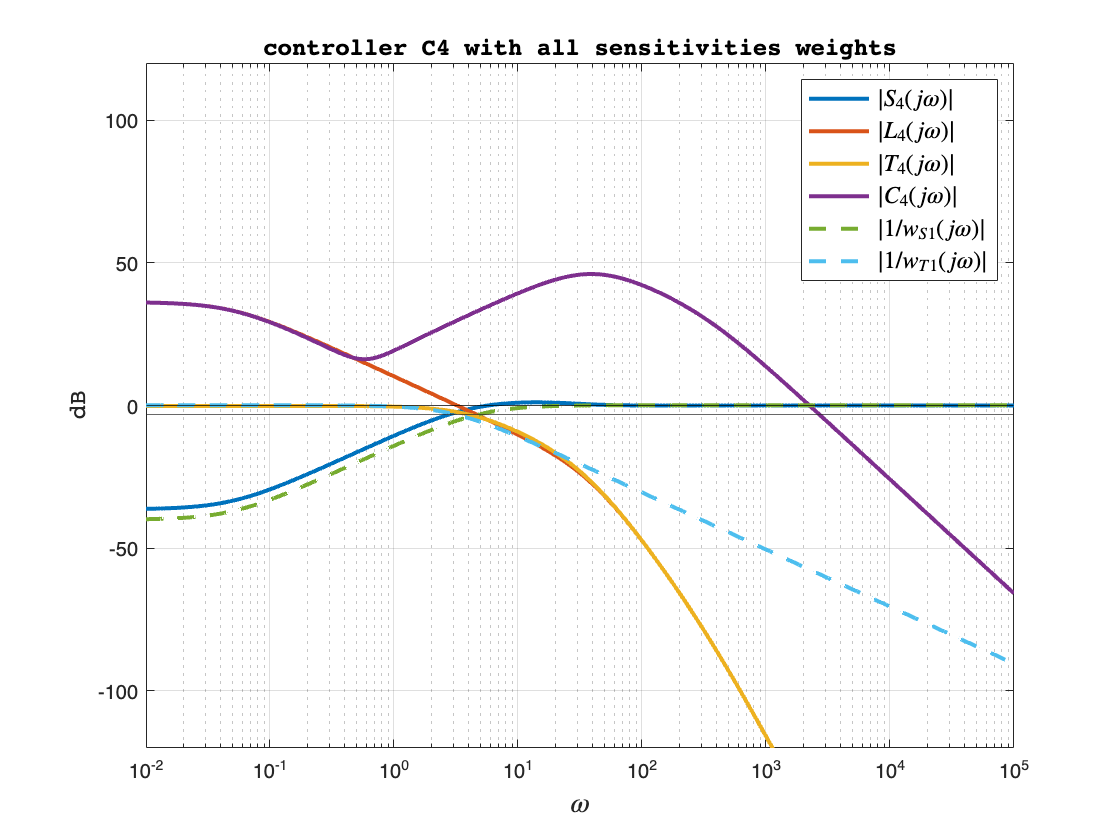

figure
plot8 = semilogx(om2,20*log10(magS4(1,:)),...
    om2,20*log10(magL4(1,:)),om2,20*log10(magT4(1,:)),...
    om2,20*log10(magC4(1,:)),om2,-20*log10(magwS1(1,:)),'--', ...
    om2,-20*log10(magwT1(1,:)),'--','LineWidth',2); grid
yline(0,'k-')
yline(-3)
ylabel('dB','FontName','courier','FontSize',12)
xlabel('$\omega$','Interpreter','latex','FontSize',14)
legC = legend('$|S_4(j\omega)|$','$|L_4(j\omega)|$','$|T_4(j\omega)|$','$|C_4(j\omega)|$','$|1/w_{S1}(j\omega)|$',...
    '$|1/w_{T1}(j\omega)|$','Interpreter','latex','Location','NorthEast');
set(legC,'FontSize',12)
title(['controller C4 with all sensitivities weights'],'FontName','courier','FontSize',12);
ylim([-120,120])
xlim([1.e-2,1.e+5])

[bandwidth(SF4.To), bandwidth(SF3.To), bandwidth(SF2.To),bandwidth(SF1.To), bandwidth(CLoop1.To)]

ans =     3.9711    4.6406    4.2098    5.0380    1.1258


Once again, the biggest underperformance is in terms of sensitivity function at low frequency, clearly above our performance weight. The desired bandwidth for our complementary sensitivity fucntion is also not met, but still reduced up to a point where its lower than all other controllers (except for the PID, of course).

We're clearly walking on a razor's edge here, since there's no room for optimization of any kind without giving up on meeting some other specifications. Let's say we're satisfied with this result for now and go on with the analysis.

## Final comparison

Let's finally compare all controllers

### Sensitivity comparison

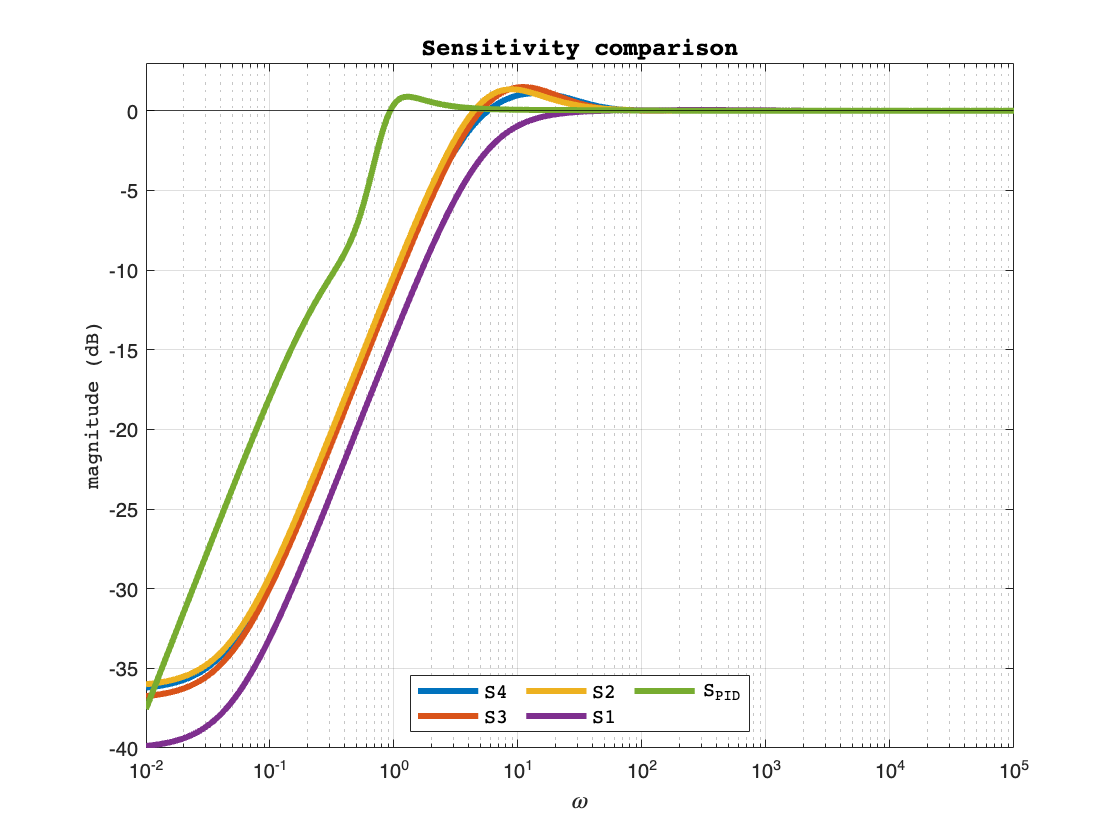

figure
semilogx(om2,20*log10(magS4(:)),om2,20*log10(magS3(:)), om2, 20*log10(magS2(:))...
    ,om2,20*log10(magS1(:)),om2, 20*log10(MagS_PID1(:)), 'LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Sensitivity comparison','FontName','courier','FontSize',12)
legend('S4','S3','S2','S1','S_{PID}','FontName','courier','FontSize',10,...
    'Location','south','NumColumns',3)
ylim([-40,3])

### Complementary Sensitivity comparison

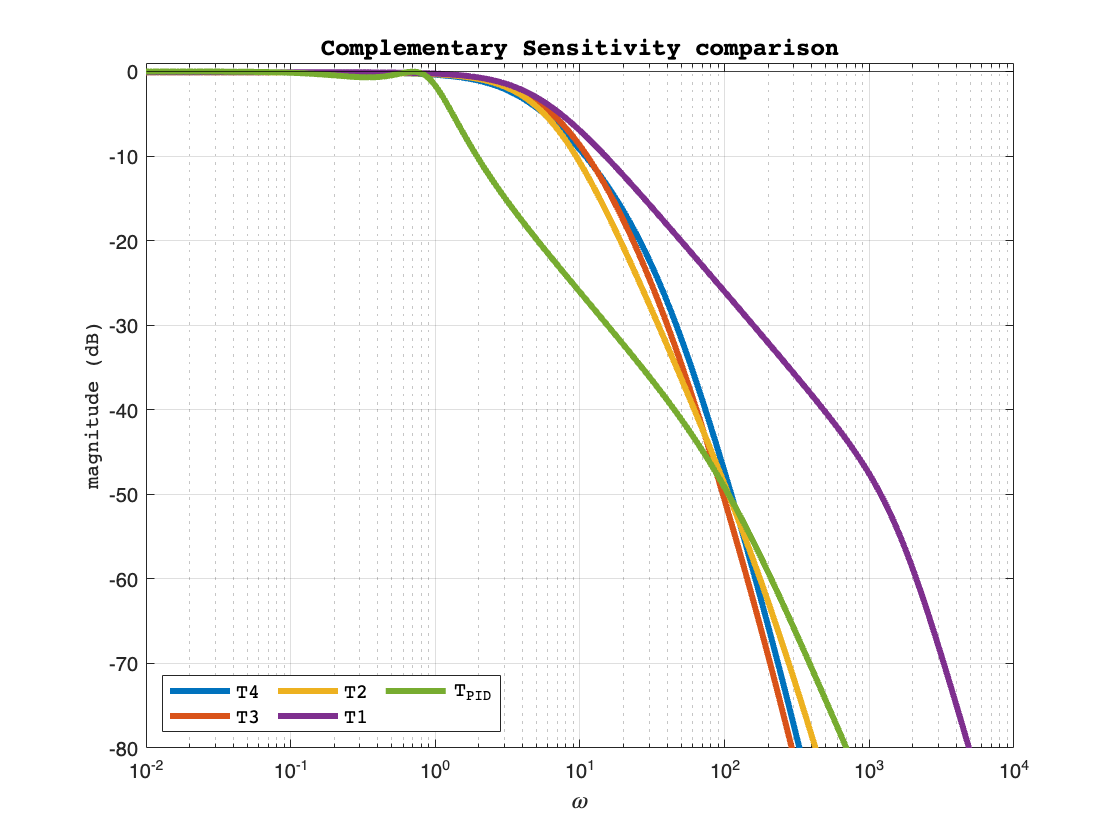

figure
semilogx(om2,20*log10(magT4(:)),om2,20*log10(magT3(:)), om2, 20*log10(magT2(:))...
    ,om2,20*log10(magT1(:)),om2, 20*log10(MagT_PID1(:)), 'LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Complementary Sensitivity comparison','FontName','courier','FontSize',12)
legend('T4','T3','T2','T1','T_{PID}','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)
ylim([-80,1])

### Control Sensitivity comparison

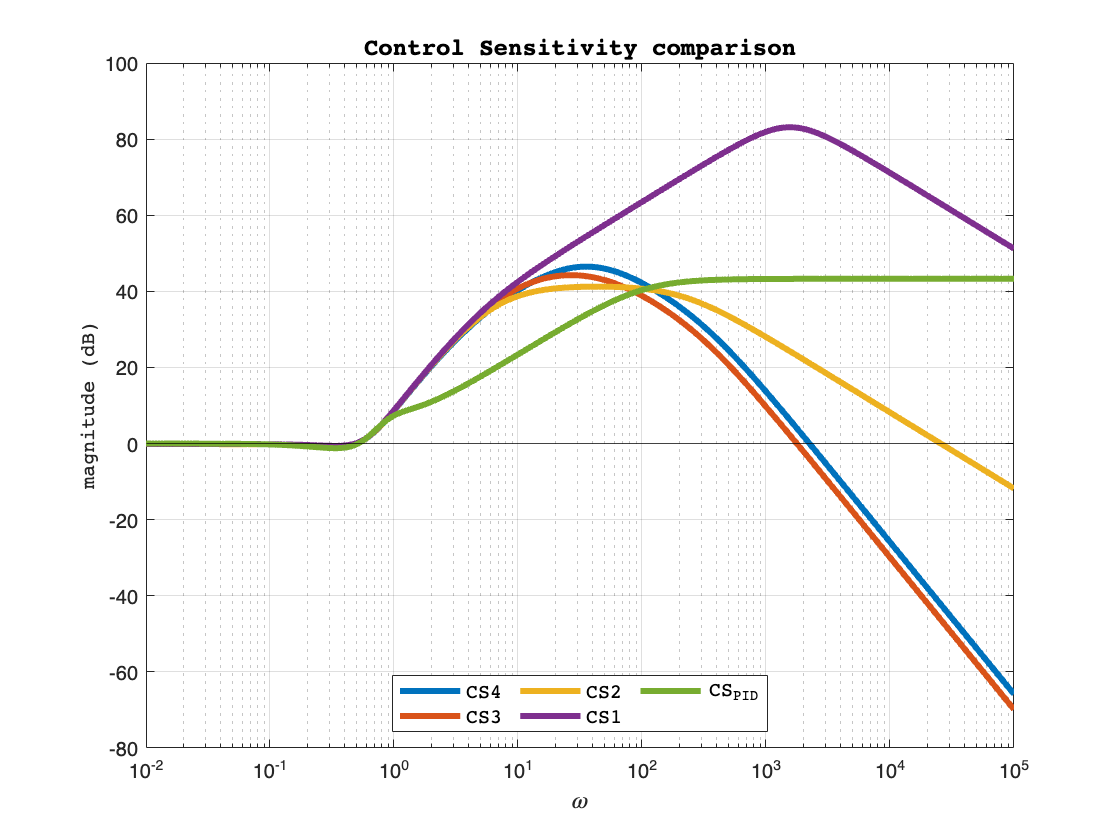

figure
semilogx(om2,20*log10(magCS4(:)),om2,20*log10(magCS3(:)), om2, 20*log10(magCS2(:))...
    ,om2,20*log10(magCS1(:)),om2, 20*log10(MagCS_PID1(:)), 'LineWidth',3); grid
yline(0,'-k');
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('magnitude (dB)','FontName','courier','FontSize',10)
title('Control Sensitivity comparison','FontName','courier','FontSize',12)
legend('CS4','CS3','CS2','CS1','CS_{PID}','FontName','courier','FontSize',10,...
    'Location','south','NumColumns',3)

Notice how reducing the bandwidth of the complementary sensitivity indirectly meant increasing the bandwidth and the peak of the control sensitivity function. Our specifications are probably a bit too strict, but this is helping us understend how compromise is necessary to find a good controller.

## Control Effort comparison

% Control effort using all sensitivity weights
[uH_4,tH4] = step(minreal(SF4.CSo),t);

3 states removed.


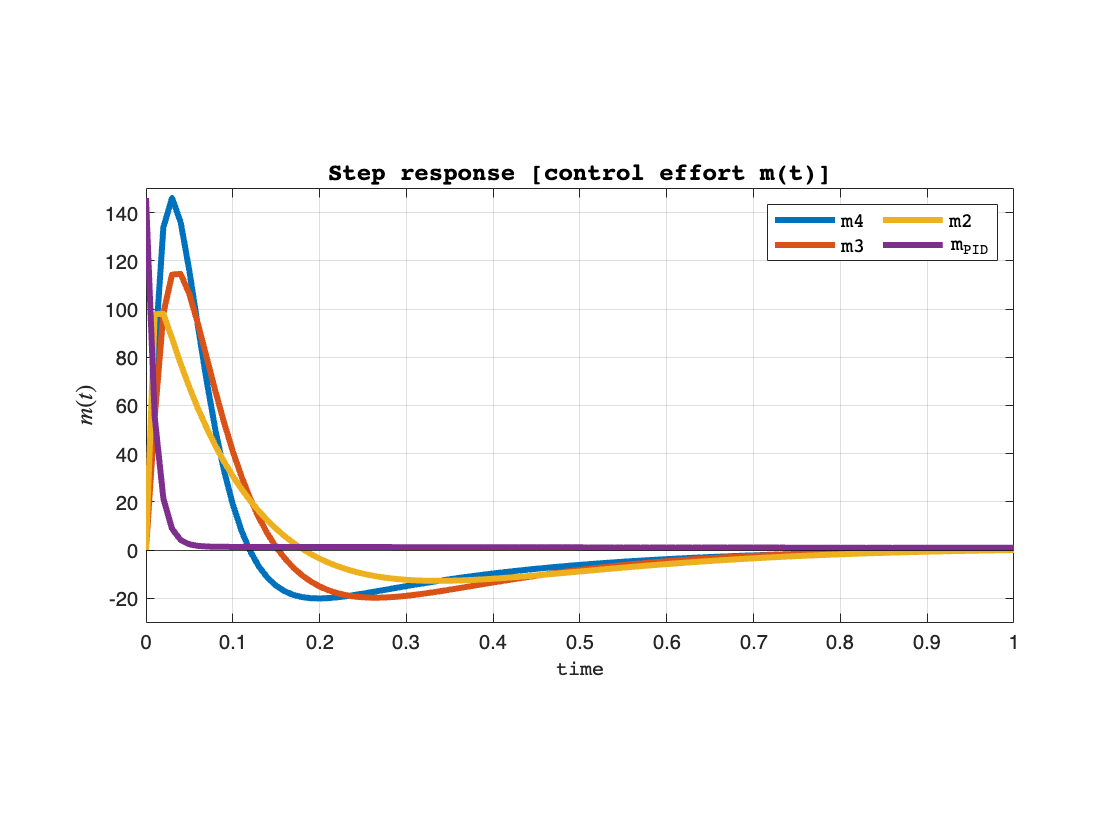


figure
plot(tH4, uH_4(:),tH3, uH_3(:),tH2, uH_2(:),t1,u1(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Step response [control effort m(t)]','FontName','courier','FontSize',12)
legend('m4','m3','m2','m_{PID}','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)
axis([0,1,-30,150])
pbaspect([2 1 1])

As expected, we've traded higher $T_o$ bandwidth for higher control effort. There's some minor discrepancy in peak value between simulink and matlab simulations, which is anyway around the value 140 (peak for the PID controller). The matlab simulation suggests a slightly worse performance with respect to that, whereas simulink evaluates the peak a couple of units below the 140 mark.

Either way, the result is the one anticipated, with more control effort needed compared to C3. Finally, let's analyse the step response of the new  $T_o \;$(i.e. the tracking beahaviour).

## Output step response comparison 

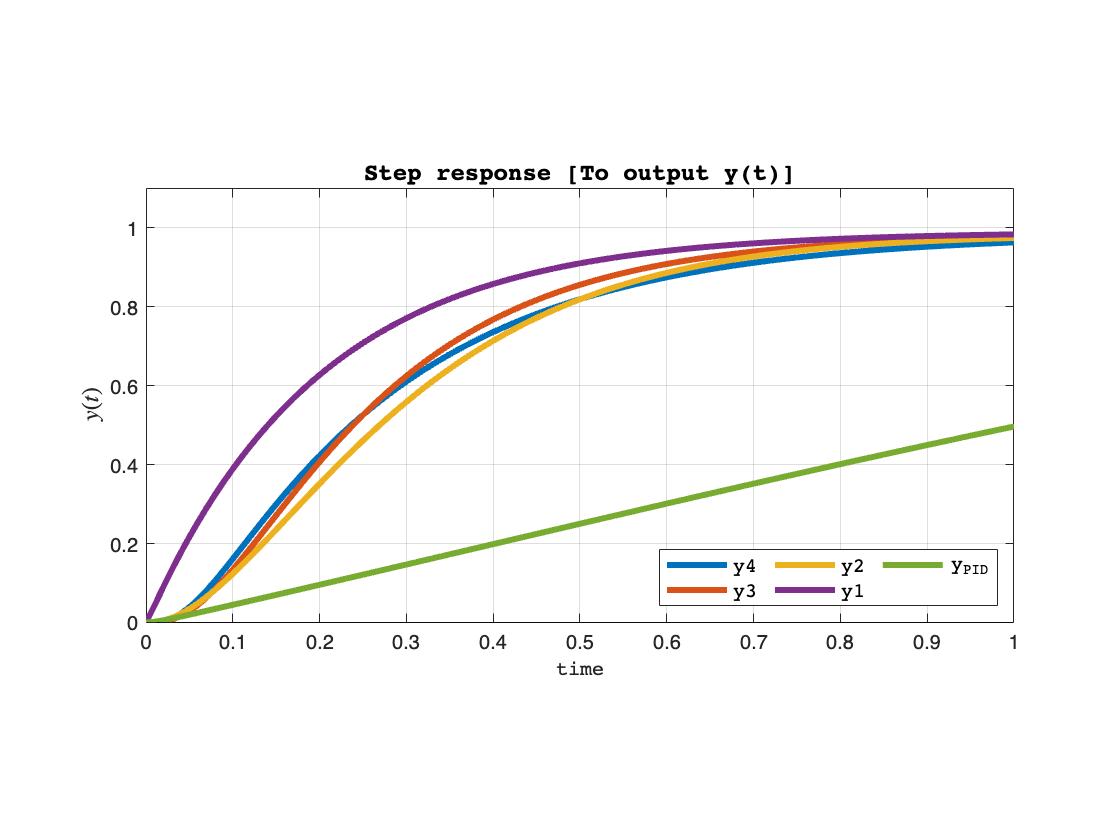

% Step response using all sensitivity weights
[yH_4,~] = step(SF4.To,t);  

figure
plot(tH4, yH_4(:),tH3, yH_3(:),tH2, yH_2(:),tH1,yH_1(:),t1,y1(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Step response [To output y(t)]','FontName','courier','FontSize',12)
legend('y4','y3','y2','y1','y_{PID}','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
axis([0,1,0,1.1])
pbaspect([2 1 1])

# Smooth step reference response

Let's analyse our controllers' performance with respect to a "smooth step", here obtained with the sigmoid function defined in the file "sigmoid_f.mat", which scales and recenters the sigmoid function to simulate a step. In particular we give as inputs (in this exact order):

- **TIMESPAN:** vector of time instants in which we want to evaluate the fucntion at

- **DELAY: **time instant in which we wish to center the step

- **STEEPNESS COEFFICIENT: **positive real number to carachterize the slope of the sigmoid function

- **INITIAL VALUE: **value of the step at time $–\;\infty$

- **FINAL VALUE: **value of the step at time +$\infty$

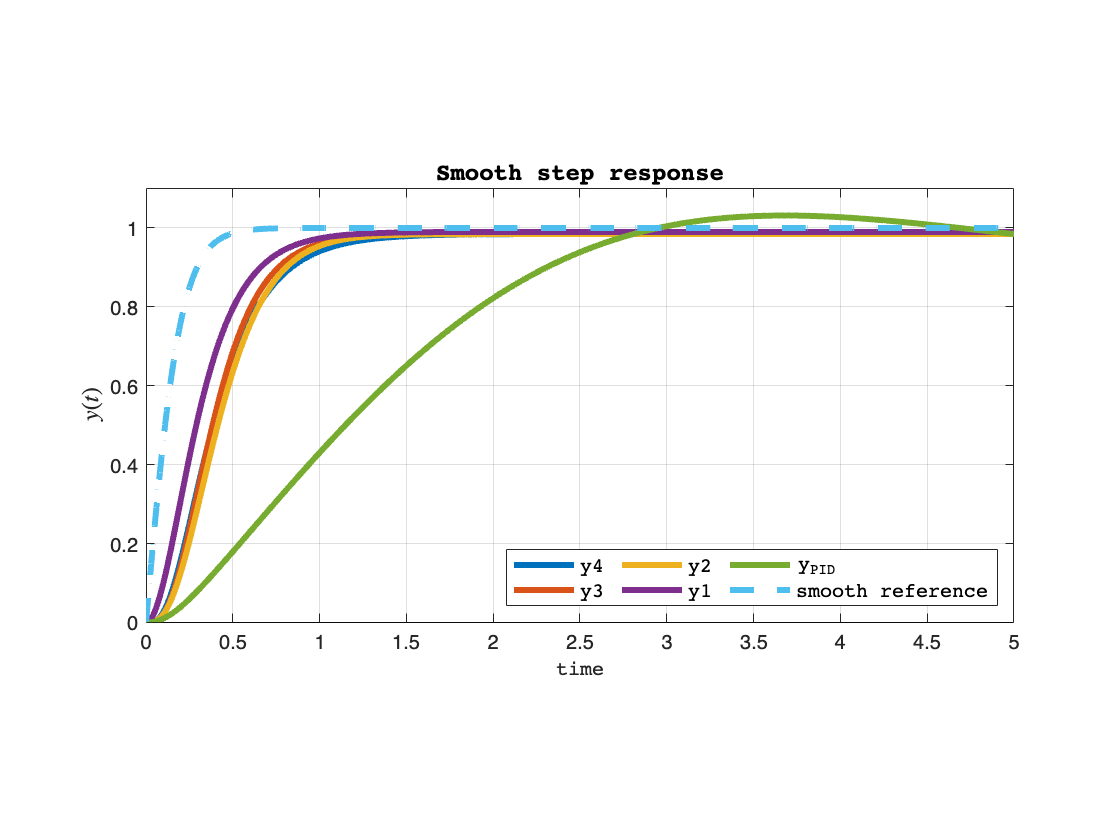

smooth_step_input = sigmoid_f(t, 0, 10, 0, 1);

% PID Controller
[ys_pid, ts_pid] = lsim(CLoop1.To, smooth_step_input, t);
[us_pid,ts_pid] = lsim(CLoop1.CSo, smooth_step_input, t);

% Controller with only wS(s)
[y1s, t1s] = lsim(SF1.To, smooth_step_input, t);
[u1s,t1s] = lsim(SF1.CSo, smooth_step_input, t);

% Controller with wS(s) and constant wSu
[y2s, t2s] = lsim(SF2.To, smooth_step_input, t);
[u2s,t2s] = lsim(SF2.CSo, smooth_step_input, t);

% Controller with wS(s) and wSu(s)
[y3s, t3s] = lsim(SF3.To, smooth_step_input, t);
[u3s,t3s] = lsim(SF3.CSo, smooth_step_input, t);

% Controller with wS(s), wSu(s) and wT(s)
[y4s, t4s] = lsim(SF4.To, smooth_step_input, t);
[u4s,t4s] = lsim(SF4.CSo, smooth_step_input, t);

% Smooth step response comparison
figure
plot(t4s,y4s, t3s,y3s, t2s,y2s,t1s,y1s,ts_pid,ys_pid,t,smooth_step_input,'--', 'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Smooth step response','FontName','courier','FontSize',12)
legend('y4','y3','y2','y1','y_{PID}','smooth reference','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
axis([0,5,0,1.1])
pbaspect([2 1 1])

As expected, due to low bandwidth and the presence of a resonance peak, the PID still presents a long and obscillating transient - with overshoot - in the response.

### Control effort

We expect a lower control effort for all controllers used so far. The PID controller should have the best performance now that the frequency content has been drastically reduced.  

C1, having no bound on the control effort, will still have an out of scale peak, so it will be left out of the graph.

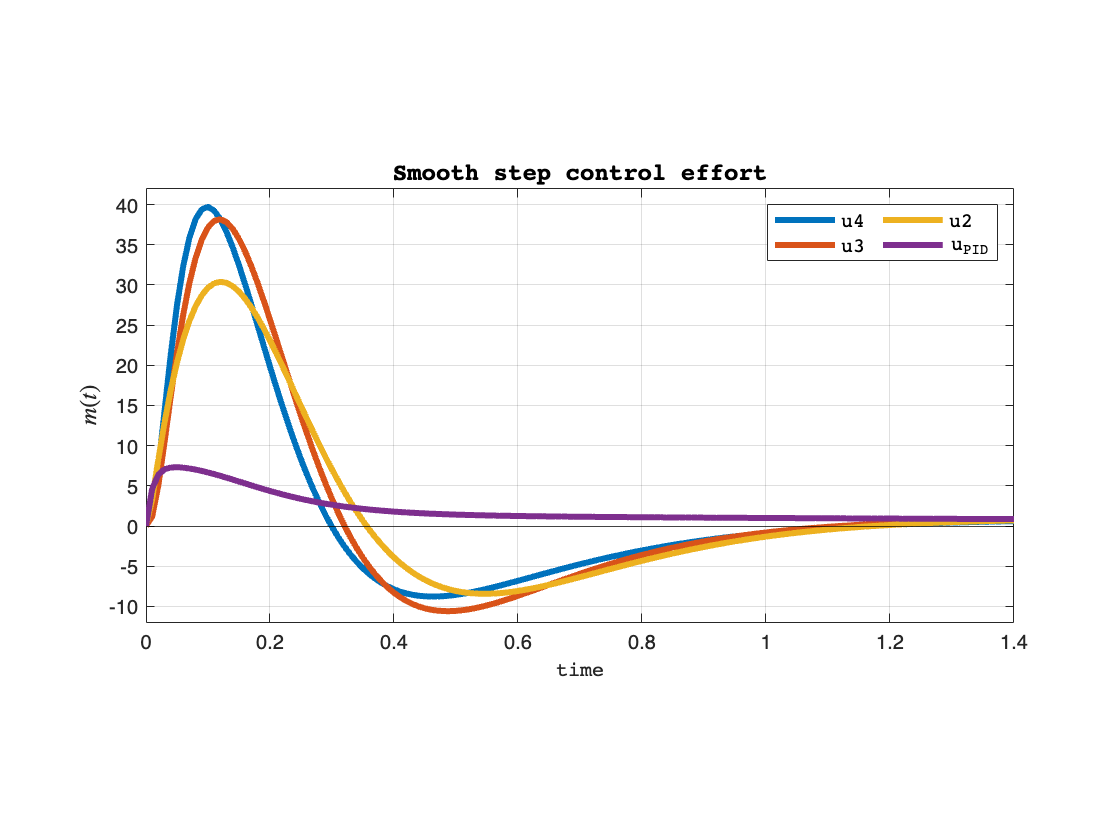

% Control effort comparison (smooth step)
figure
plot(t4s,u4s, t3s,u3s,t2s,u2s,ts_pid,us_pid, 'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Smooth step control effort','FontName','courier','FontSize',12)
legend('u4','u3','u2','u_{PID}','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)
axis([0,1.4,-12,42])
pbaspect([2 1 1])

# Sinusoidal reference

Our analysis so far has not taken into account sinusoidal references. However, we've previously mentioned that the bandwidth specifications we have imposed will allow "acceptable" tracking only at low frequencies.

We could think of completely redesigning our controller imposing high bandwidth for the sensitivities, but this would make us "weak" in terms of measurement noise rejection and very demanding in terms of control effort.

Let's define three frequencies of oscillation to understand the behaviour of our system with respect to sinusoidal references.

%% w1 = 0.1; w2 = 1; w3 = 10
omegas = [0.1; 1; 10];

Let's see how the Complementary sensitivities are at these frequencies

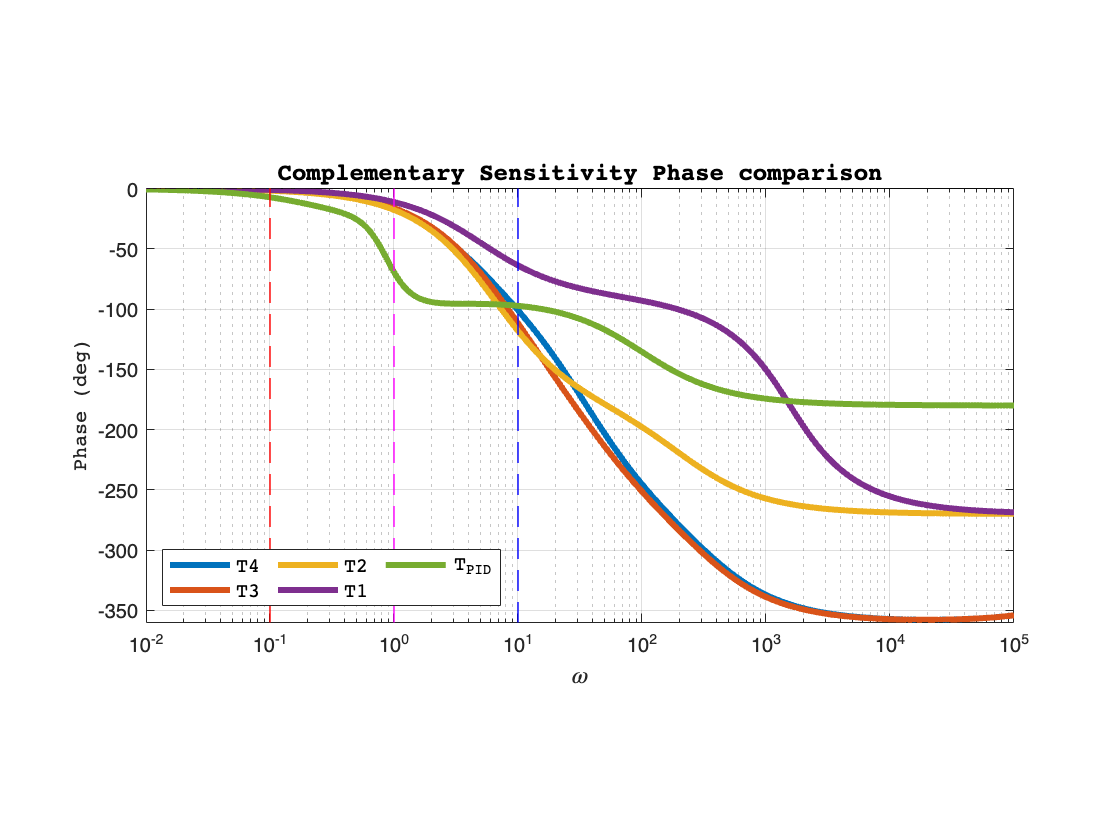

% Complementary sensitivities comparison: Phase
figure
semilogx(om2,phaseT4(:),om2,phaseT3(:), om2, phaseT2(:)...
    ,om2,phaseT1(:),om2, PhaseT_PID1(:), 'LineWidth',3); grid
yline(0,'-k');
xline(0.1,'r--','Linewidth', 1);
xline(1,'m--','Linewidth', 1);
xline(10,'b--','Linewidth', 1);
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('Phase (deg)','FontName','courier','FontSize',10)
title('Complementary Sensitivity Phase comparison','FontName','courier','FontSize',12)
ylim([-360,0])
legend('T4','T3','T2','T1','T_{PID}','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)
pbaspect([2 1 1])

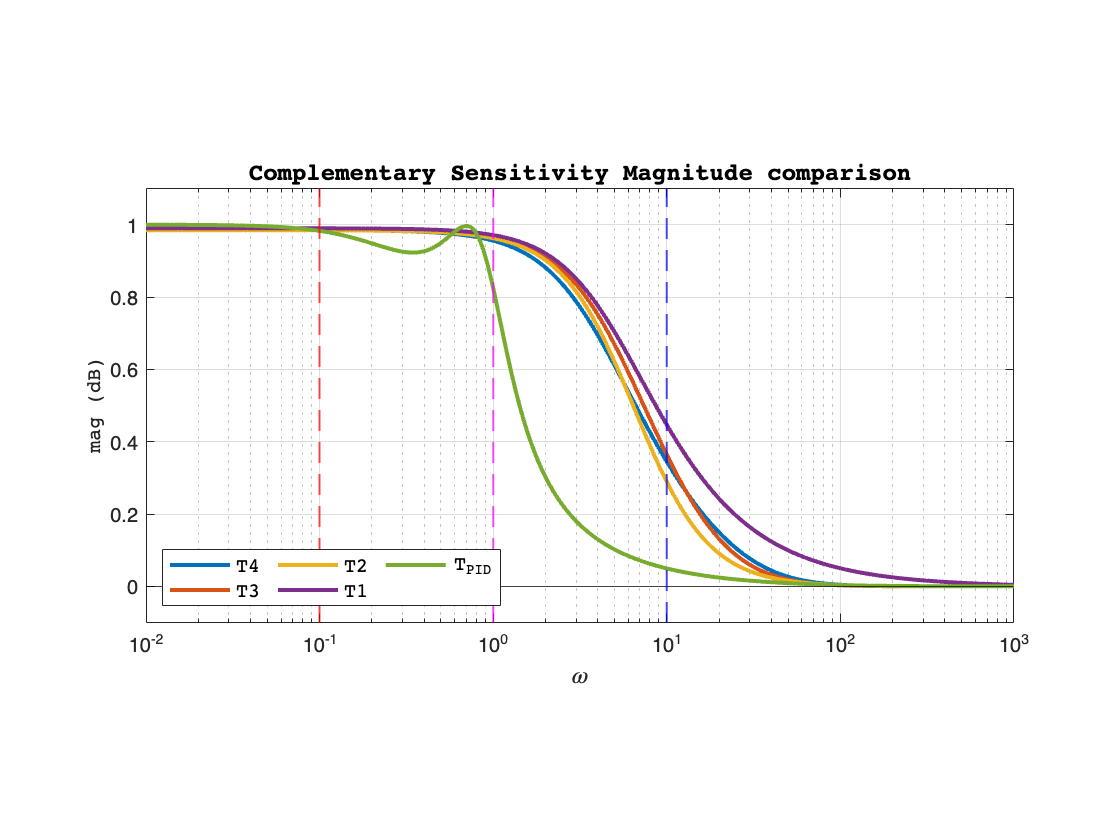


% Complementary sensitivities comparison: Magnitude
figure()
semilogx(om2,magT4(:),om2,magT3(:), om2, magT2(:)...
    ,om2,magT1(:),om2, MagT_PID1(:), 'LineWidth',2); grid
yline(0,'-k');
xline(0.1,'r--','Linewidth', 1);
xline(1,'m--','Linewidth', 1);
xline(10,'b--','Linewidth', 1);
xlabel('$\omega$','Interpreter','latex','FontSize',12)
ylabel('mag (dB)','FontName','courier','FontSize',10)
title('Complementary Sensitivity Magnitude comparison','FontName','courier','FontSize',12)
legend('T4','T3','T2','T1','T_{PID}','FontName','courier','FontSize',10,...
    'Location','southwest','NumColumns',3)
ylim([-0.1,1.1])

xlim([1e-2,1e3])
pbaspect([2 1 1])

## Sinusoidal reference response

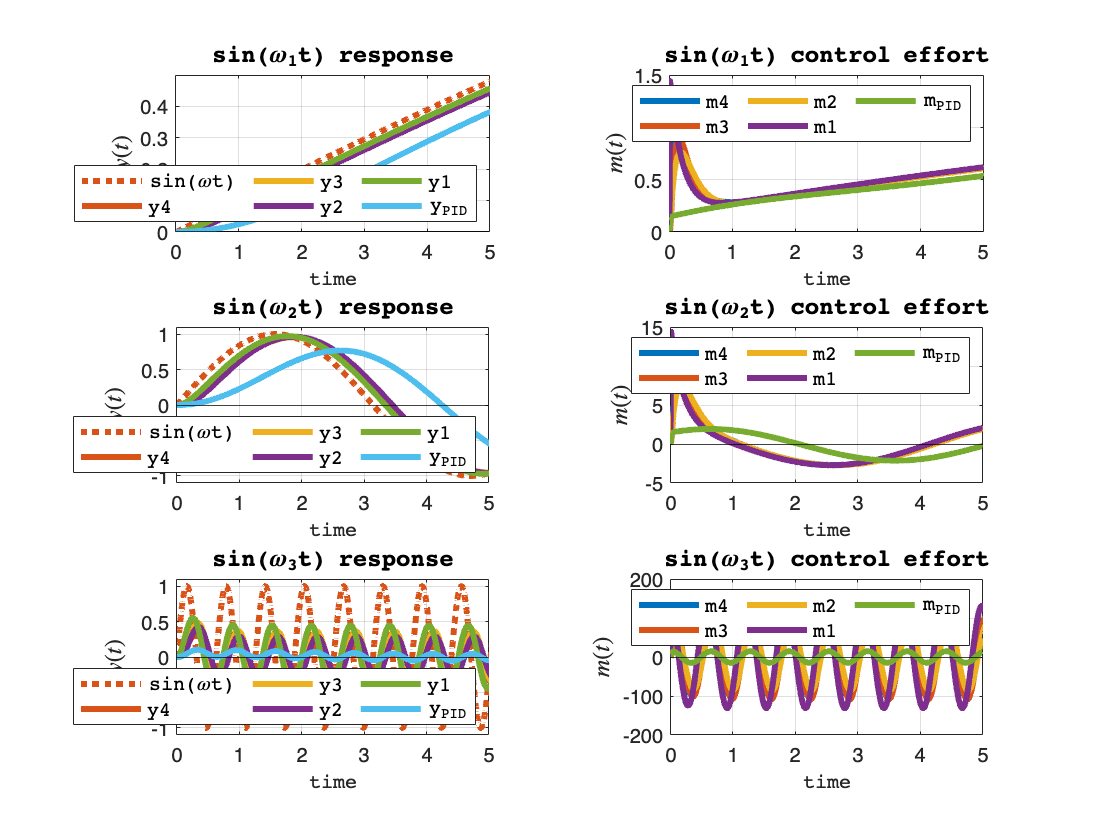

NMatlabRed = [0.8500   0.3250   0.0980];

% Create output vector
ys_pid = zeros(length(t), length(omegas));
y1s = ys_pid;
y2s = ys_pid;
y3s = ys_pid;
y4s = ys_pid;

figure

% Sinusoidal reference response
for i = 1:length(omegas)
    % For each frequency, compute the reference vector
    ui = sin(omegas(i)*t);
    
    % ____ PID Controller ____ 
    [ys_pid, ts_pid] = lsim(CLoop1.To, ui, t); % output response
    [us_pid,~] = lsim(CLoop1.CSo, ui, t); % control effort
    
    % ____ Controller with only wS(s) ____ 
    [y1s, t1s] = lsim(SF1.To, ui, t); % output response
    [u1s,~] = lsim(SF1.CSo, ui, t); % control effort
    
    % ____ Controller with wS(s) and constant wSu ____ 
    [y2s, t2s] = lsim(SF2.To, ui, t); % outputresponse
    [u2s,~] = lsim(SF2.CSo, ui, t); % control effort    
    
    % ____ Controller with wS(s) and wSu(s) ____ 
    [y3s, t3s] = lsim(SF3.To, ui, t); % output response
    [u3s,~] = lsim(SF3.CSo, ui, t); % control effort
    
    % ____ Controller with wS(s), wSu(s) and wT(s) ____ 
    [y4s, t4s] = lsim(SF4.To, ui, t); % output response
    [u4s,~] = lsim(SF4.CSo, ui, t); % control effort
    
    % Plot reference vs response
    subplot(3,2,2*i-1)
    plot(t, ui(:), ':','Color', NMatlabRed,'LineWidth', 3)
    hold on
    plot(t4s, y4s(:), t3s, y3s(:), t2s, y2s(:), t1s, y1s(:), ts_pid, ys_pid(:), 'LineWidth', 3); 
    grid;
    yline(0,'-k');
    xlabel('time','FontName','courier','FontSize',10)
    ylabel('$y(t)$','Interpreter','latex','FontSize',12)
    if i==1
    axis([0,5,0,0.5])
    else
    axis([0,5,-1.1,1.1])
    end
    hold off
    pbaspect([2 1 1])
    title(['sin(\omega_',num2str(i),'t) response'],'FontName','courier','FontSize',12)
    legend('sin(\omegat)','y4','y3','y2','y1','y_{PID}','FontName','courier','FontSize',10,...
        'Location','southeast','NumColumns',3)
    
    % Plot control effort comparison
    subplot(3,2,2*i)
    plot(t4s, u4s(:), t3s, u3s(:), t2s, u2s(:), t1s, u1s(:), ts_pid, us_pid(:), 'LineWidth', 3); 
    grid;
    yline(0,'-k');
    xlabel('time','FontName','courier','FontSize',10)
    ylabel('$m(t)$','Interpreter','latex','FontSize',12)
    title(['sin(\omega_',num2str(i),'t) control effort'],'FontName','courier','FontSize',12)
    legend('m4','m3','m2','m1','m_{PID}','FontName','courier','FontSize',10,...
        'Location','northeast','NumColumns',3)
    xlim([0,5])
    pbaspect([2 1 1])
    end

Tracking error seems to be close to null at low frequency ($\left.\omega =0\ldotp 1\right)\;\ldotp$ At frequency 1 we can see that the PID controller introduces a module attenuation and a phase shift that are too remarked and completely undemine the tracking. As for the $H_\infty$ controllers, there's a certain attenuation and phase, but the reference is tracked in good approximation. At frequency 10, all controllers fail to track the reference since there's a 90 degree phase, but the PID in particular almost completely rejects it due to module attenuation. 

Let's visualize the error dynamics to better see these results.

### Tracking Error Comparison

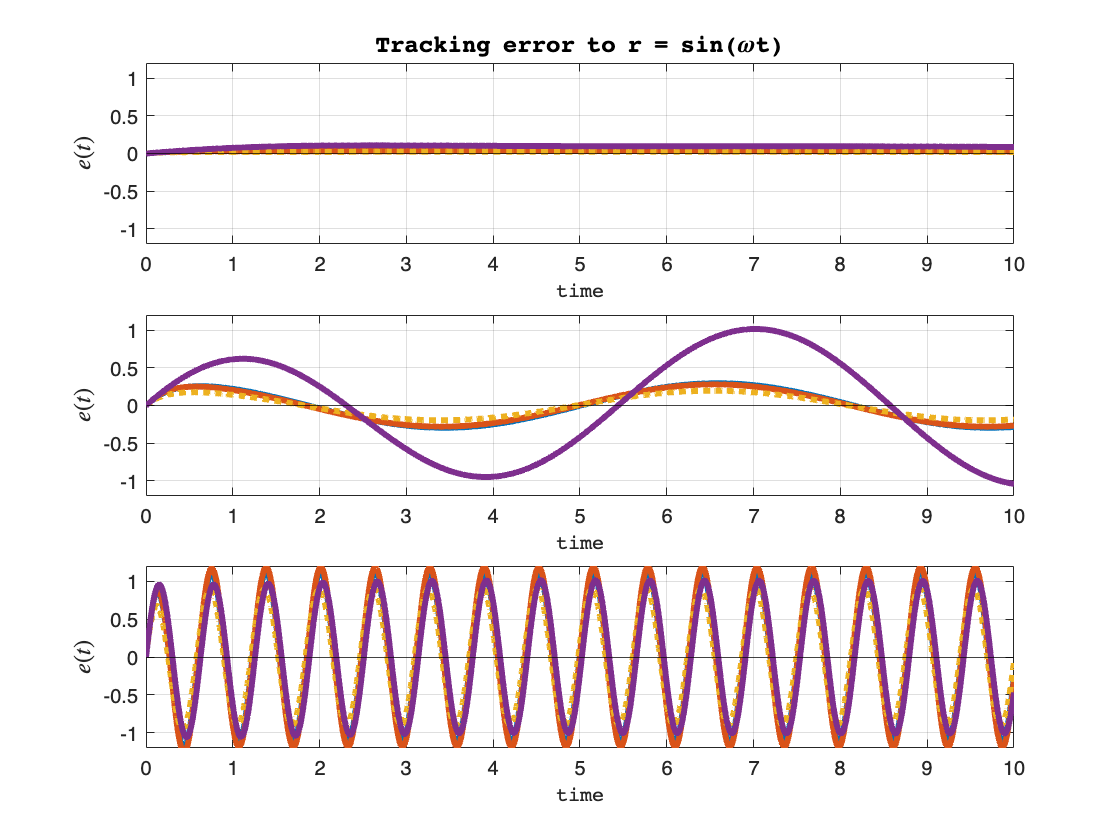

% Visualize control effort
for i = 1:3
ui = sin(omegas(i)*t);

[es_pid, ~] = lsim(CLoop1.So, ui, t);
[e1s, ~] = lsim(SF1.So, ui, t);
[e3s, ~] = lsim(SF3.So, ui, t);
[e4s, ~] = lsim(SF4.So, ui, t);

subplot(3, 1, i)
plot(t4s,e4s(:),t3s,e3s(:),t1s,e1s(:),':',ts_pid,es_pid(:), 'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$e(t)$','Interpreter','latex','FontSize',12)
axis([0,10,-1.2,1.2])
end
subplot(3,1,1);
title('Tracking error to r = sin(\omegat)','FontName','courier','FontSize',12)

                                                        

As expected, the error is acceptable only at low frequency. Even at $\omega =1$ there's a tracking error that oscillates between $\pm 30%$ for the $H_\infty$ controllers and $\pm 100%$ for the PID (due to phase shift).

Let's see the same scenario in terms of control effort to see if sinusoidal tracking is realizable at least at low frequency.

# Noisy reference

To model some 

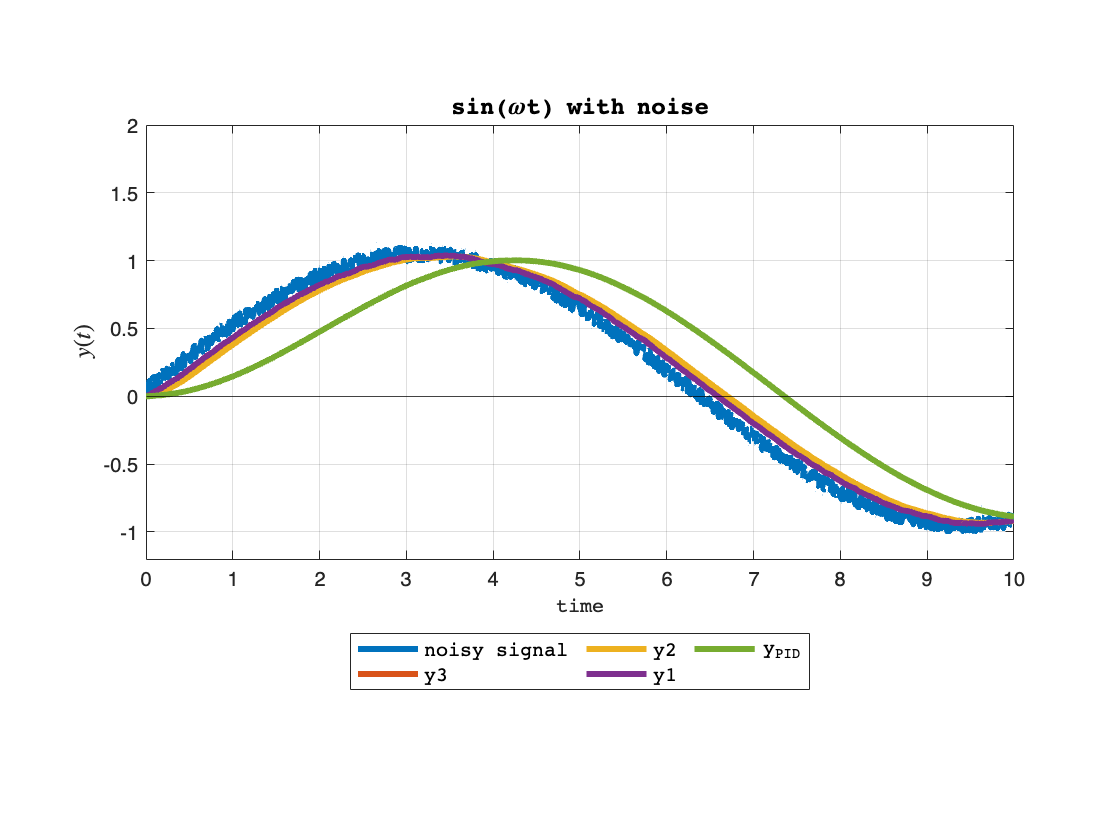

n = sin(0.5*t)+0.1*rand(size(t));
[y1n, t1n] = lsim(CLoop1.To, n, t1);
[y2n,t2n] = lsim(SF1.To, n, t1);
[y3n,t3n] = lsim(SF2.To, n, t1);
[y4n,t4n] = lsim(SF3.To, n, t1);

figure
plot(t, n,t4n,y4n(:),t3n,y3n(:),t2n,y2n(:),t1n,y1n(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('sin(\omegat) with noise','FontName','courier','FontSize',12)
legend('noisy signal','y3','y2', 'y1','y_{PID}','FontName','courier','FontSize',10,...
    'Location','southoutside','NumColumns',3)
axis([0,10,-1.2,2])
pbaspect([2 1 1])

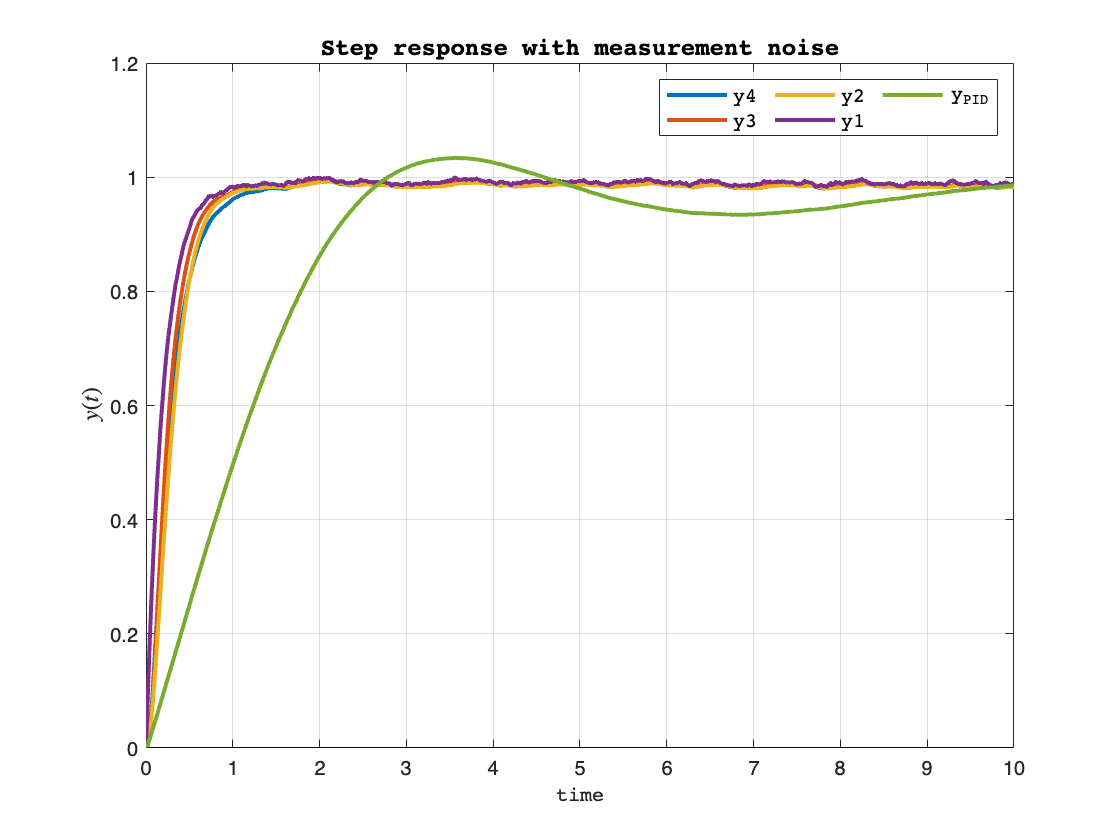

% Load Noisy Step response generated in simulink
folder = 'Data';

filelist = dir(fullfile(folder, '*.mat'));

for i = 1:numel(filelist)
    filename = fullfile(folder, filelist(i).name);
    load(filename);
end

% Plot response
figure
plot(y_n4(1,:),y_n4(2,:),y_n3(1,:),y_n3(2,:),y_n2(1,:),y_n2(2,:),y_n1(1,:),y_n1(2,:),y_nPID1(1,:),y_nPID1(2,:),'LineWidth',2); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('Step response with measurement noise','FontName','courier','FontSize',12)
legend('y4','y3','y2', 'y1','y_{PID}','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)

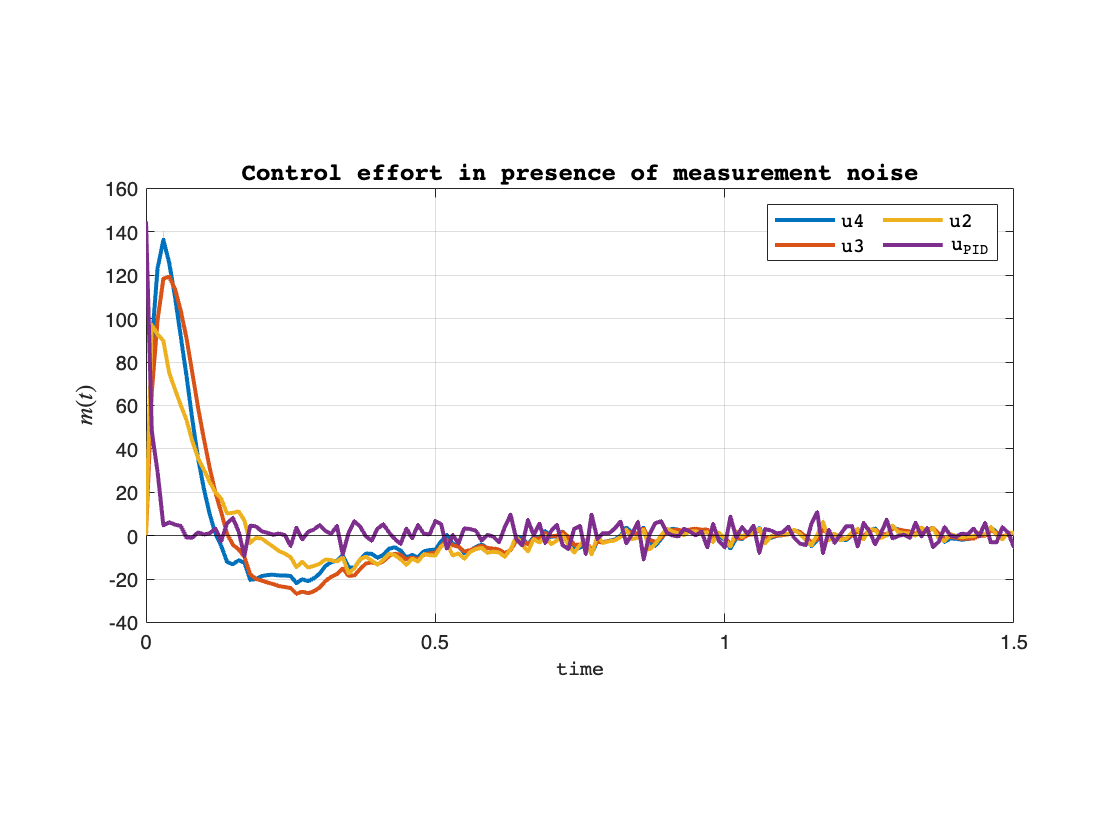

% Control effort
figure
plot(u_n4(1,:),u_n4(2,:),u_n3(1,:),u_n3(2,:),u_n2(1,:),u_n2(2,:),u_nPID1(1,:),u_nPID1(2,:),'LineWidth',2); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('Control effort in presence of measurement noise','FontName','courier','FontSize',12)
legend('u4','u3','u2','u_{PID}','FontName','courier','FontSize',10,...
    'Location','northeast','NumColumns',3)
xlim([0,1.5])
pbaspect([2 1 1])